addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
        dataMobilityFull = 'Data\HAMR6_SE2_kinematicMobility_full.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
        dataMobilityFull = 'Data\case_1_kinematicMobility_full.mat';
end
if exist(dataName, "file")
    load(dataName);
else
    error(['ERROR! The base kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx".']);
end
if exist(dataMotPlanName, "file")
    load(dataMotPlanName);
else
    error(['ERROR! The motion planning kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx" (last section).']);
end

submanifoldIndex = 5;
integrationTime = 1.2*ones(1, 2);
refPtOrg = zeros(1, 2);

FRHLstance = Path2_Mobility(submanifoldIndex, ...
                    kin, kinfunc, p_kin, p_info, ...
                    integrationTime, refPtOrg, ...
                    'NoPhaseLimits', 'branched');

FLHRstance = Path2_Mobility.constructComplementaryStance...
                    (FRHLstance, ...
                    kin, kinfunc, p_kin, p_info, ...
                    integrationTime, refPtOrg, ...
                    'NoPhaseLimits', 'branched');

% if exist(dataMobilityFull, "file")
%     save(dataMobilityFull, "FRHLstance", "FLHRstance", "-append");
% else
%     save(dataMobilityFull, "FRHLstance", "FLHRstance");
% end

We have the mobility formulation defined now.

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
        dataMobilityFull = 'Data\HAMR6_SE2_kinematicMobility_full.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
        dataMobilityFull = 'Data\case_1_kinematicMobility_full.mat';
end
if exist(dataName, "file")
    load(dataName);
else
    error(['ERROR! The base kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx".']);
end
if exist(dataMotPlanName, "file")
    load(dataMotPlanName);
else
    error(['ERROR! The motion planning kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx" (last section).']);
end
if exist(dataMobilityFull, "file")
    load(dataMobilityFull);
else
    error(['ERROR! The mobility kinematics data file is needed. ' ...
        'Create one in the first section of this livescript.']);
end

## Overall reachable sets

Here, we obtain the alternating gait reachable sets for a quadrupedal nonslip trotting gait.

% input discretization
% ... this is the discretization for scaling and sliding parameter
% ... dimensions
dNumU = 11; % 9, 

% number of F-levelsets to explore
% ... here we choose the discretization for the number of F-levelsets to
% ... explore, this will form a 2D grid for the levelsets on each stance
% ... phase
dNumLeaves = 11; % 9, 

% alternating gait instance
rigidTrot = altQuadGait(FRHLstance, FLHRstance, ...
    "multi-F-levelsets", ...
    "path_limit_compliant", ...
    [-1.2, 1.2], fh2_b__i, dNumU) % 1.2 amplitude % 1.8 amp

rigidTrot =   altQuadGait with properties:

              ithStance: [1×1 Path2_Mobility]
              jthStance: [1×1 Path2_Mobility]
    leafExplorationMode: "multi-F-levelsets"
              numLeaves: 11
              inputMode: 'path_limit_compliant'
    bodyToLimbTransform: {1×4 cell}
      integrationLimits: [-1.2000 1.2000]
            stanceSpace: [1×1 struct]
             inputSpace: []



%  integration times for each stance phase, used in the
%  "generateInputSpace" function call
T = repmat({-1.2*ones(1, 2)}, 1, 2); % -1.2 % -1.8

% reachable and mobility set construction
rigidTrot = altQuadGait.generateInputSpace( rigidTrot, dNumU, T );
tic; rigidTrot = altQuadGait.simulateInputSpace( rigidTrot ); toc;

Elapsed time is 23.706994 seconds.



% compute the cost as a function of the input space
% ... same size as "inputSpace.sim.z{iComp}" in "inputSpace.J.vel{iComp}" 
% ... or "inputSpace.J.accln{iComp}"
rigidTrot = altQuadGait.computeGaitCost( rigidTrot );

% compute the mobility set
% ... same size and structure as "inputSpace.sim.z"
rigidTrot = altQuadGait.computeMobility(rigidTrot, 'sim');

% flatten the reachable and mobility sets
[refPt, F, u, ~, zX, zY, zYaw, Ex, Ey, Eyaw] = ...
                                altQuadGait.flattenMobilityStructs(rigidTrot, 'sim');

% % Save the instance once more
% if exist(dataMobilityFull, 'file')
%     save(dataMobilityFull, "rigidTrot", ... % alt quad gait instance
%                            "refPt", "F", "u", ... % reference point, F-value, and scaling/sliding params
%                            "zX", "zY", "zYaw", ... % reachable set componentwise
%                            "Ex", "Ey", "Eyaw", ... % mobility set componentwise (substructs: vel, accln)
%                            "-append"); 
% else
%     save(dataMobilityFull, "rigidTrot", ...
%                            "refPt", "F", "u", ...
%                            "zX", "zY", "zYaw", ...
%                            "Ex", "Ey", "Eyaw"); 
% end

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
        dataMobilityFull = 'Data\HAMR6_SE2_kinematicMobility_full.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
        dataMobilityFull = 'Data\case_1_kinematicMobility_full.mat';
end
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
if exist(dataName, "file")
    load(dataName);
else
    error(['ERROR! The base kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx".']);
end
if exist(dataMotPlanName, "file")
    load(dataMotPlanName);
else
    error(['ERROR! The motion planning kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx" (last section).']);
end
if exist(dataMobilityFull, "file")
    load(dataMobilityFull);
else
    error(['ERROR! The mobility kinematics data file is needed. ' ...
        'Create one in the first section of this livescript.']);
end

Elapsed time is 239.927435 seconds.


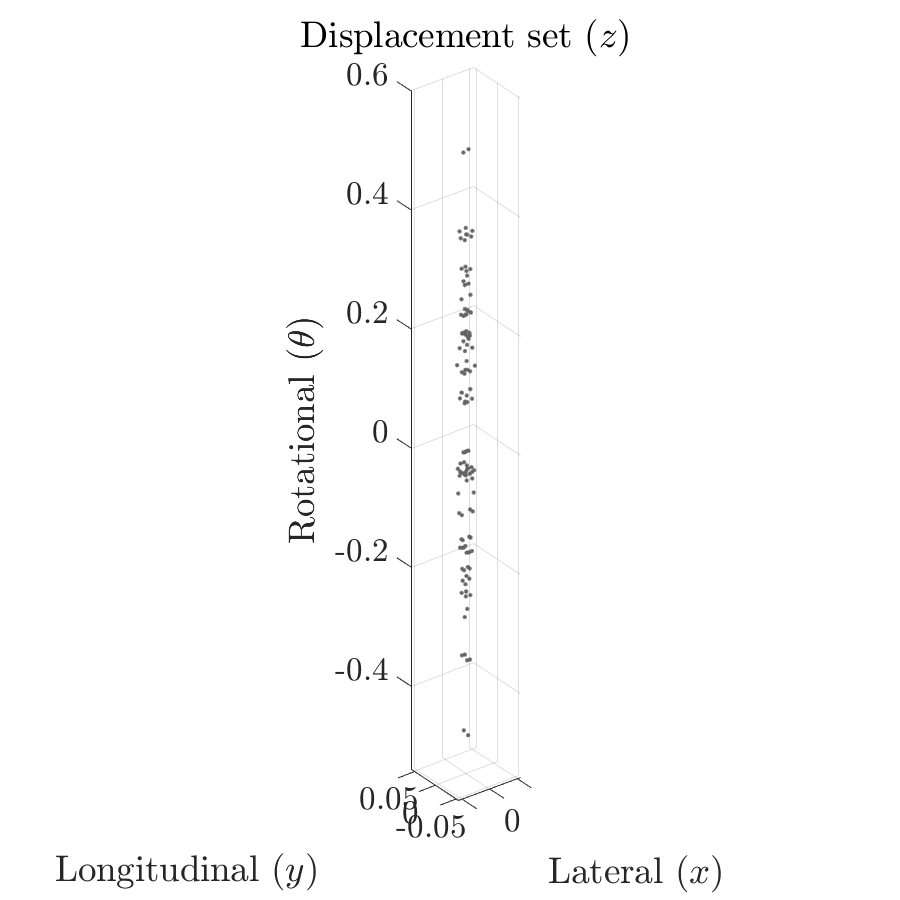

% obtain boundaries and other information for plotting the 3D reachability
% and mobility sets, and their 2D projections
tic;
z = {zX, zY, zYaw};
zX = z{1}(:); zY = z{2}(:); zYaw = z{3}(:);
Evel = {Ex.vel, Ey.vel, Eyaw.vel};
EvelX = Evel{1}(:); EvelY = Evel{2}(:); EvelYaw = Evel{3}(:);
Eaccln = {Ex.accln, Ey.accln, Eyaw.accln};
EacclnX = Eaccln{1}(:); EacclnY = Eaccln{2}(:); EacclnYaw = Eaccln{3}(:);
fullyShrunkBoundary3D = boundary(zX, zY, zYaw, 1);
fullyShrunkBoundary2D = cell(1, 3); idxCyclic = 1:3;
for i = 1:3
    fullyShrunkBoundary2D{i} = boundary(z{idxCyclic(1)}(:), z{idxCyclic(2)}(:), 1);
    idxCyclic = circshift(idxCyclic, -1);
end
fullyShrunkBoundary3D_Evel = boundary(EvelX, EvelY, EvelYaw, 1);
fullyShrunkBoundary2D_Evel = cell(1, 3); idxCyclic = 1:3;
for i = 1:3
    fullyShrunkBoundary2D_Evel{i} = boundary(Evel{idxCyclic(1)}(:), Evel{idxCyclic(2)}(:), 1);
    idxCyclic = circshift(idxCyclic, -1);
end
fullyShrunkBoundary3D_Eaccln = boundary(EacclnX, EacclnY, EacclnYaw, 1);
fullyShrunkBoundary2D_Eaccln = cell(1, 3); idxCyclic = 1:3;
for i = 1:3
    fullyShrunkBoundary2D_Eaccln{i} = boundary(Eaccln{idxCyclic(1)}(:), Eaccln{idxCyclic(2)}(:), 1);
    idxCyclic = circshift(idxCyclic, -1);
end
dirnLabelTxt = {'Lateral ($x$)', 'Longitudinal ($y$)', 'Rotational ($\theta$)'};
toc;

Reachable Set

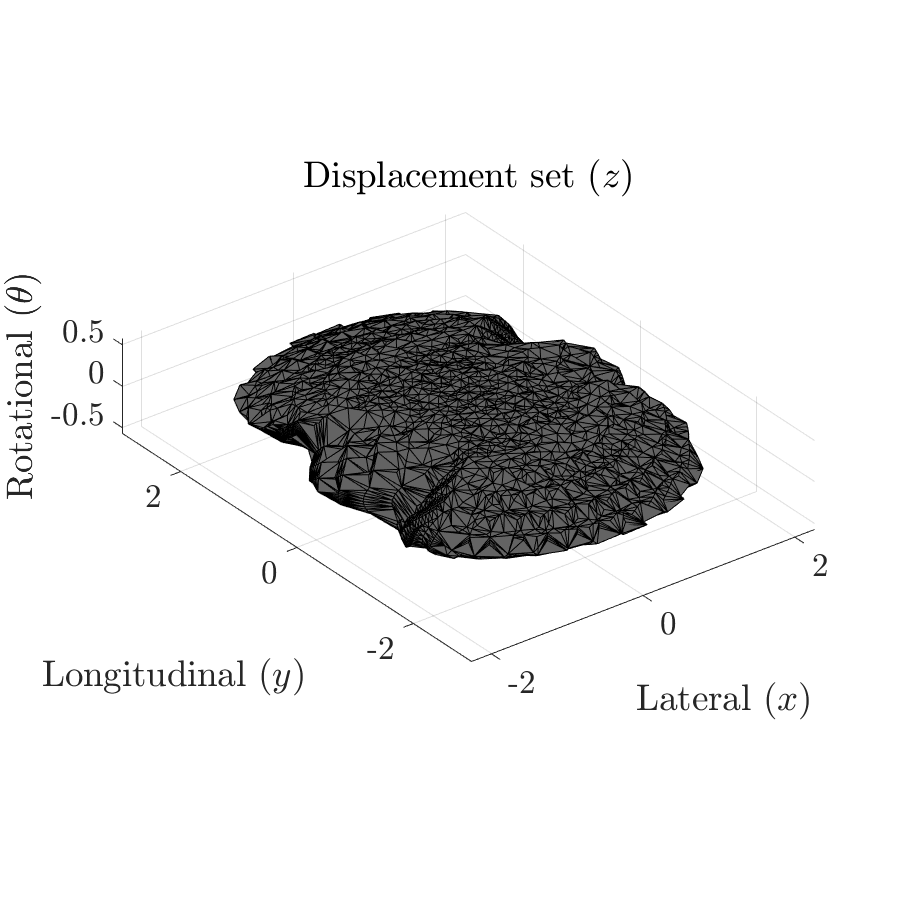

fS = 25; panelFaceColor = 99/255*ones(1, 3);
figure('units', 'pixels', 'position', [0 0 900 900], ...
                'Color','w','Visible','on'); ax = gca;
trisurf(fullyShrunkBoundary3D, zX, zY, zYaw, ...
    'LineWidth', 0.1, 'LineStyle', '-', 'FaceColor', panelFaceColor);
axis(ax, "equal", "padded"); ax.FontSize = fS; title(ax, 'Displacement set ($z$)');
xlabel(ax, dirnLabelTxt{1}); ylabel(ax, dirnLabelTxt{2}); zlabel(ax, dirnLabelTxt{3});

Mobility set - velocity version

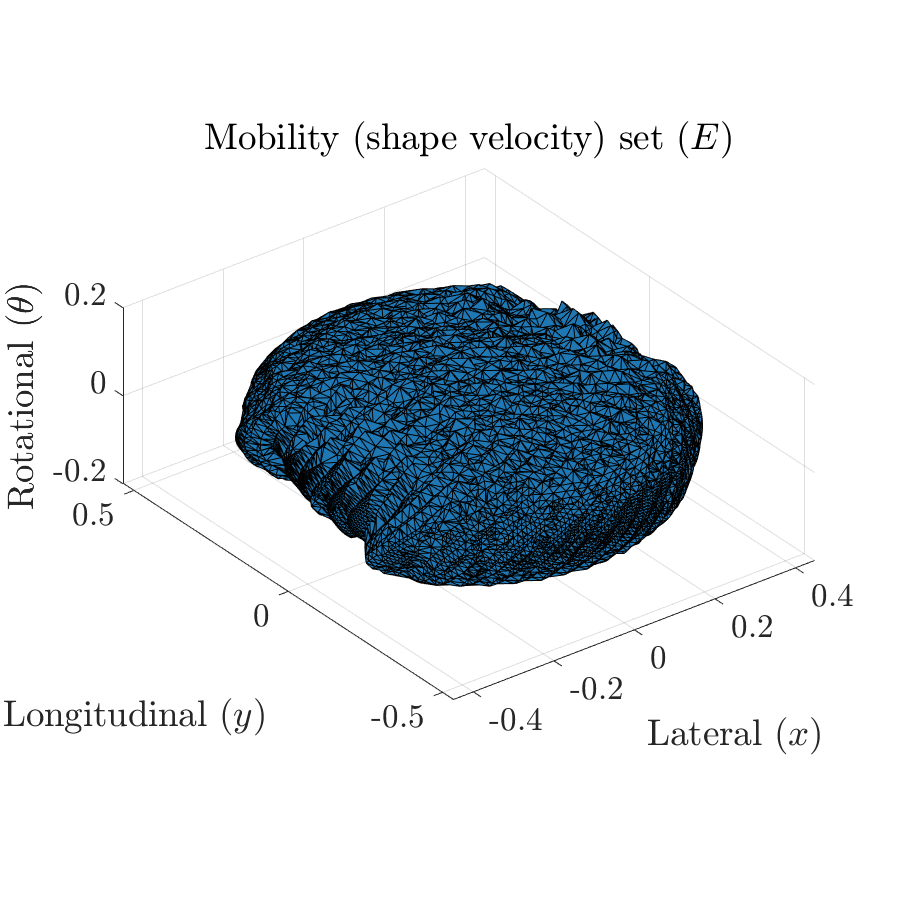

fS = 25; panelFaceColor = [31,120,180]/255;
figure('units', 'pixels', 'position', [0 0 900 900], ...
                'Color','w','Visible','on'); ax = gca;
trisurf(fullyShrunkBoundary3D_Evel, EvelX, EvelY, EvelYaw, ...
    'LineWidth', 0.1, 'LineStyle', '-', 'FaceColor', panelFaceColor);
axis(ax, "equal", "padded"); ax.FontSize = fS; title(ax, 'Mobility (shape velocity) set ($E$)');
xlabel(ax, dirnLabelTxt{1}); ylabel(ax, dirnLabelTxt{2}); zlabel(ax, dirnLabelTxt{3});

Mobility set - acceleration version

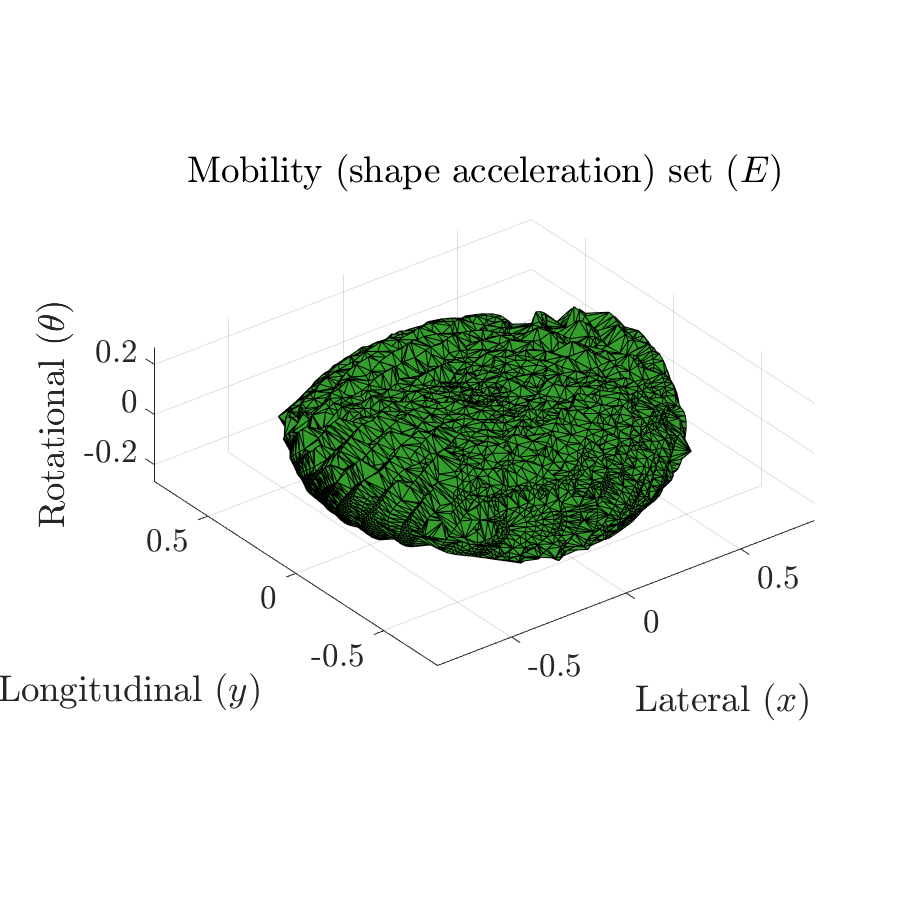

fS = 25; panelFaceColor = [51,160,44]/255;
figure('units', 'pixels', 'position', [0 0 900 900], ...
                'Color','w','Visible','on'); ax = gca;
trisurf(fullyShrunkBoundary3D_Eaccln, EacclnX, EacclnY, EacclnYaw, ...
    'LineWidth', 0.1, 'LineStyle', '-', 'FaceColor', panelFaceColor);
axis(ax, "equal", "padded"); ax.FontSize = fS; title(ax, 'Mobility (shape acceleration) set ($E$)');
xlabel(ax, dirnLabelTxt{1}); ylabel(ax, dirnLabelTxt{2}); zlabel(ax, dirnLabelTxt{3});

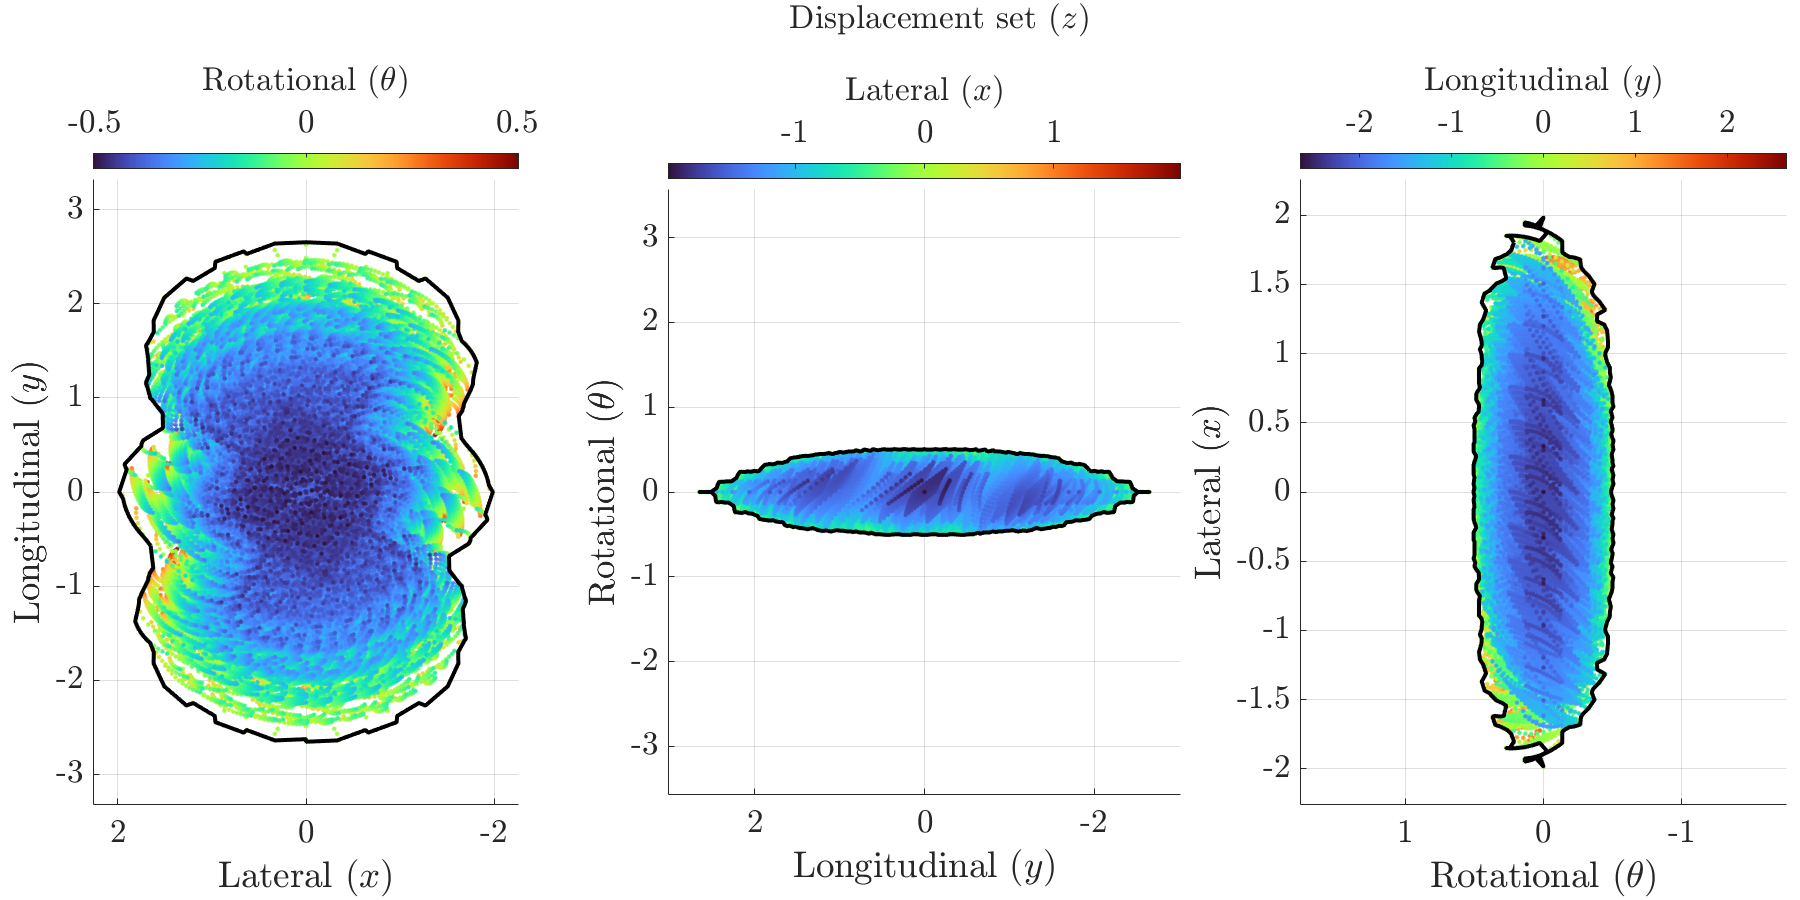

outOfAxisDirn = 'descend'; % ascend  % descend

fS = 25;
f = figure('units', 'pixels', 'position', [0 0 1800 900], ...
                'Color','w','Visible','on');
tl = tiledlayout(f, 1, 3, "TileSpacing", "tight", "Padding", "tight");
idxCyclic = 1:3;
for i = 1:3
    idxHorz = idxCyclic(1); zHorzNow = z{idxHorz}(:); dirnHorzTxt = dirnLabelTxt{idxHorz};
        idxVert = idxCyclic(2); zVertNow = z{idxVert}(:); dirnVertTxt = dirnLabelTxt{idxVert};
            idxOut = idxCyclic(3); zOutNow = z{idxOut}(:); dirnOutTxt = dirnLabelTxt{idxOut};       
    bound2Dnow = fullyShrunkBoundary2D{i};
    [~, iOut] = sort(zOutNow, 1, outOfAxisDirn);
    cLimNow = [min(zOutNow), max(zOutNow)];
    X = linspace(cLimNow(1), cLimNow(2), size(turbo, 1))';
    colNow = interpColorAndCondition(X, turbo, zOutNow);
    ax = nexttile(tl); hold(ax, "on"); grid(ax, "on");
    scatter(ax, zHorzNow(iOut), zVertNow(iOut), 100, colNow(iOut, :), 'Marker', '.');
    plot(ax, zHorzNow(bound2Dnow), zVertNow(bound2Dnow), 'k-', 'LineWidth', 3.0);
    axis(ax, "equal", "padded"); ax.FontSize = fS;
    xlabel(ax, dirnHorzTxt);
    ylabel(ax, dirnVertTxt); 
    colormap(ax, "turbo"); clim(ax, cLimNow); 
    cb = colorbar(ax, "northoutside", 'FontSize', fS); 
    cb.Label.String = dirnOutTxt; cb.Label.Interpreter = "latex";
    cb.TickLabelInterpreter = "latex";
    if strcmp(outOfAxisDirn, 'descend')
        ax.XDir = "reverse";
    end
    idxCyclic = circshift(idxCyclic, -1);
end
title(tl, 'Displacement set ($z$)', 'FontSize', fS, 'Interpreter', 'latex');

The maximum and minimum displacements in each direction ($z_{\phi}^{x}$, $z_{\phi}^{y}$, and $z_{\phi}^{\theta}$) are given by,

lateral_displacement_limits = [min(zX), max(zX)]

lateral_displacement_limits =    -1.9847    1.9847


longitudinal_displacement_limits = [min(zY), max(zY)]

longitudinal_displacement_limits =    -2.6538    2.6538


rotational_displacement_limits = [min(zYaw), max(zYaw)]

rotational_displacement_limits =    -0.5053    0.5053


translational_anisotropy = diff(longitudinal_displacement_limits)/diff(lateral_displacement_limits)

translational_anisotropy = 1.3371

Velocity Mobility

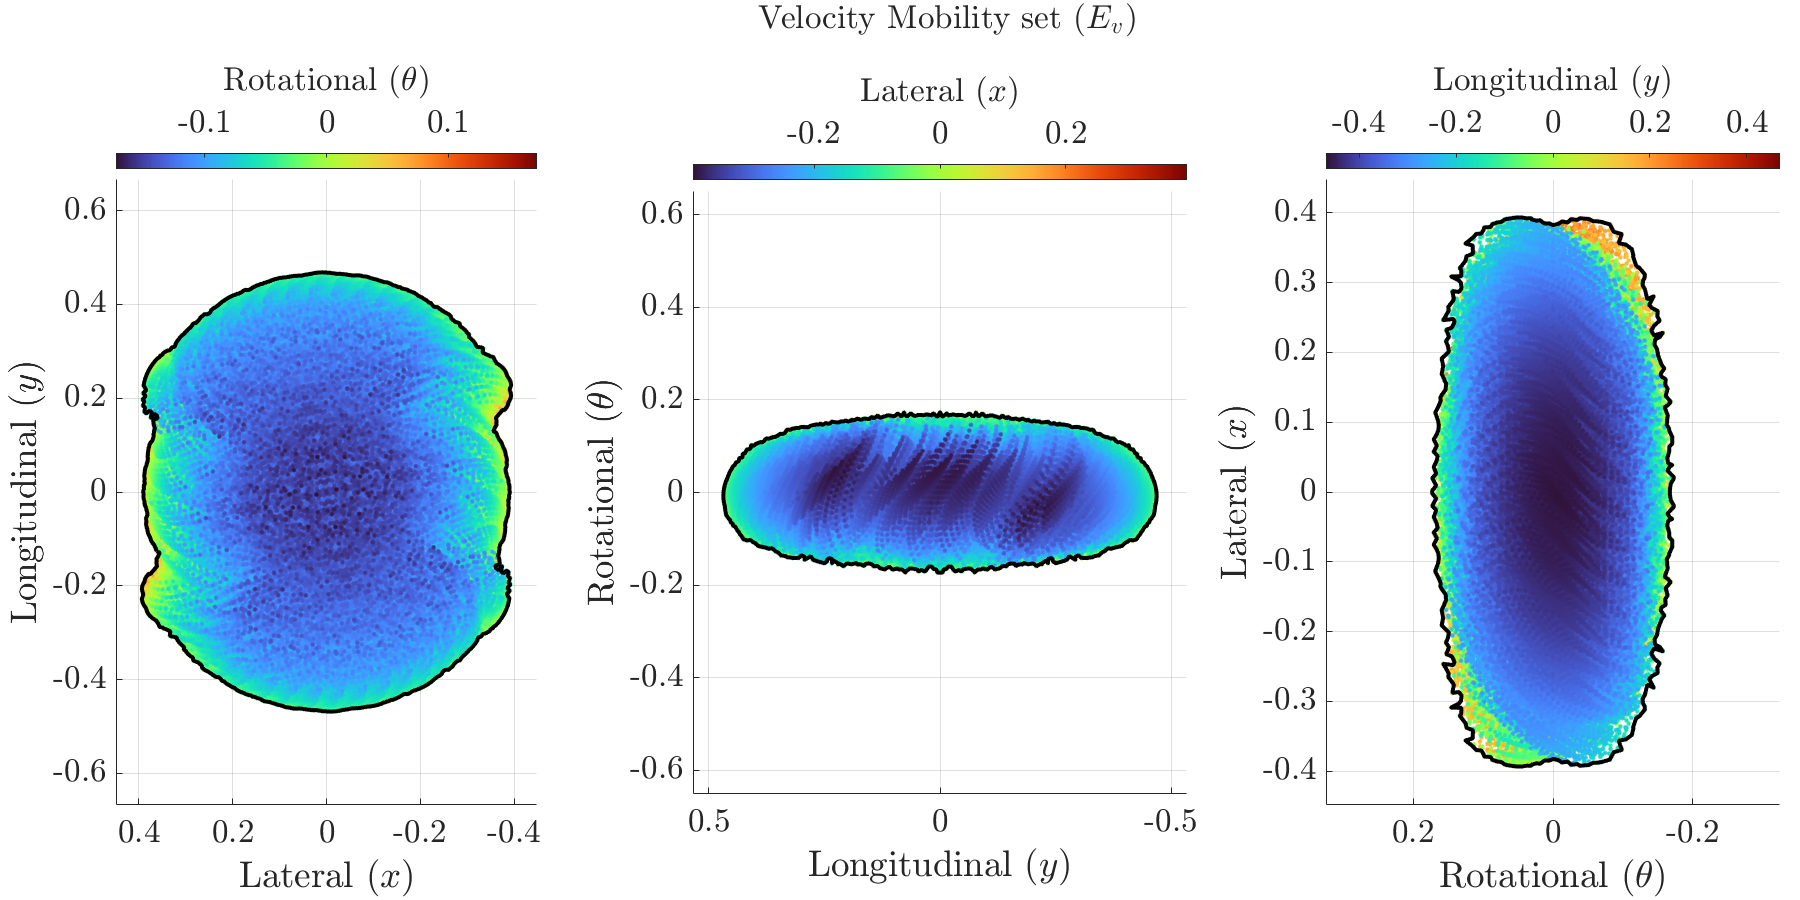

fS = 25;
f = figure('units', 'pixels', 'position', [0 0 1800 900], ...
                'Color','w','Visible','on');
tl = tiledlayout(f, 1, 3, "TileSpacing", "tight", "Padding", "tight");
idxCyclic = 1:3;
for i = 1:3
    idxHorz = idxCyclic(1); zHorzNow = Evel{idxHorz}(:); dirnHorzTxt = dirnLabelTxt{idxHorz};
        idxVert = idxCyclic(2); zVertNow = Evel{idxVert}(:); dirnVertTxt = dirnLabelTxt{idxVert};
            idxOut = idxCyclic(3); zOutNow = Evel{idxOut}(:); dirnOutTxt = dirnLabelTxt{idxOut};       
    bound2Dnow = fullyShrunkBoundary2D_Evel{i};
    [~, iOut] = sort(zOutNow, 1, outOfAxisDirn);
    cLimNow = [min(zOutNow), max(zOutNow)];
    X = linspace(cLimNow(1), cLimNow(2), size(turbo, 1))';
    colNow = interpColorAndCondition(X, turbo, zOutNow);
    ax = nexttile(tl); hold(ax, "on"); grid(ax, "on");
    scatter(ax, zHorzNow(iOut), zVertNow(iOut), 100, colNow(iOut, :), 'Marker', '.');
    plot(ax, zHorzNow(bound2Dnow), zVertNow(bound2Dnow), 'k-', 'LineWidth', 3.0);
    axis(ax, "equal", "padded"); ax.FontSize = fS;
    xlabel(ax, dirnHorzTxt);
    ylabel(ax, dirnVertTxt); 
    colormap(ax, "turbo"); clim(ax, cLimNow); 
    cb = colorbar(ax, "northoutside", 'FontSize', fS); 
    cb.Label.String = dirnOutTxt; cb.Label.Interpreter = "latex";
    cb.TickLabelInterpreter = "latex";
    if strcmp(outOfAxisDirn, 'descend')
        ax.XDir = "reverse";
    end
    idxCyclic = circshift(idxCyclic, -1);
end
title(tl, 'Velocity Mobility set ($E_v$)', 'FontSize', fS, 'Interpreter', 'latex');

lateral_displacement_limits = [min(EvelX), max(EvelX)]

lateral_displacement_limits =    -0.3935    0.3935


longitudinal_displacement_limits = [min(EvelY), max(EvelY)]

longitudinal_displacement_limits =    -0.4681    0.4681


rotational_displacement_limits = [min(EvelYaw), max(EvelYaw)]

rotational_displacement_limits =    -0.1731    0.1731


translational_anisotropy = diff(longitudinal_displacement_limits)/diff(lateral_displacement_limits)

translational_anisotropy = 1.1896

Acceleration Mobility

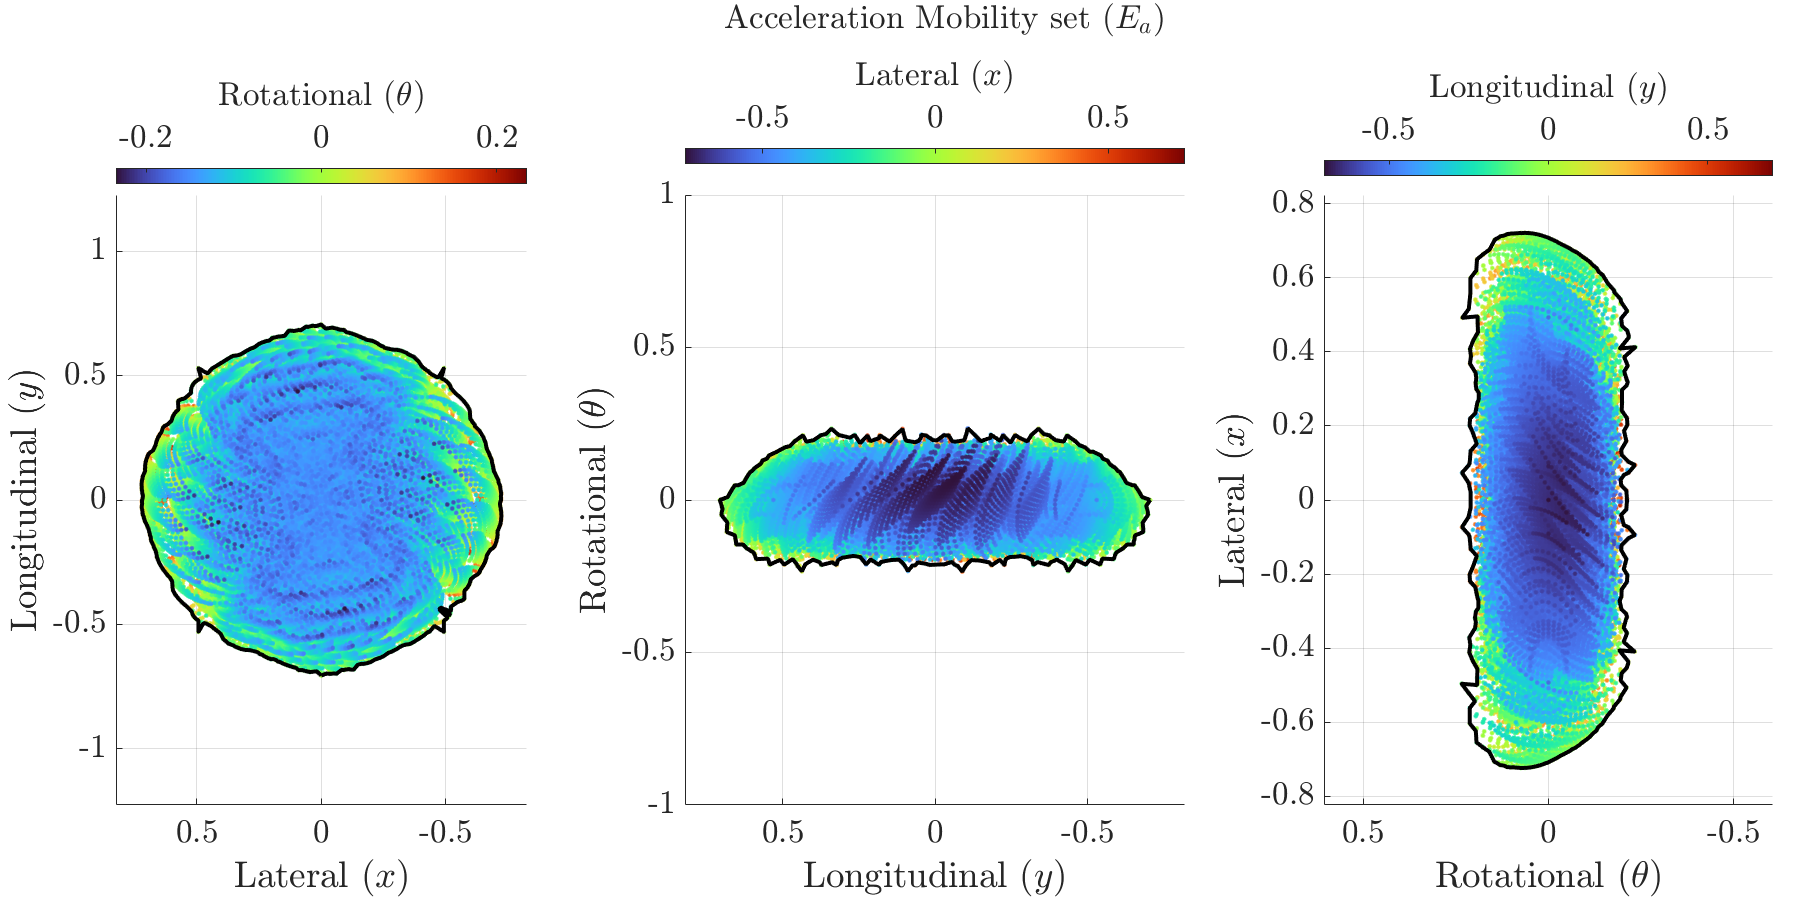

fS = 25;
f = figure('units', 'pixels', 'position', [0 0 1800 900], ...
                'Color','w','Visible','on');
tl = tiledlayout(f, 1, 3, "TileSpacing", "tight", "Padding", "tight");
idxCyclic = 1:3;
for i = 1:3
    idxHorz = idxCyclic(1); zHorzNow = Eaccln{idxHorz}(:); dirnHorzTxt = dirnLabelTxt{idxHorz};
        idxVert = idxCyclic(2); zVertNow = Eaccln{idxVert}(:); dirnVertTxt = dirnLabelTxt{idxVert};
            idxOut = idxCyclic(3); zOutNow = Eaccln{idxOut}(:); dirnOutTxt = dirnLabelTxt{idxOut};       
    bound2Dnow = fullyShrunkBoundary2D_Eaccln{i};
    [~, iOut] = sort(zOutNow, 1, outOfAxisDirn);
    cLimNow = [min(zOutNow), max(zOutNow)];
    X = linspace(cLimNow(1), cLimNow(2), size(turbo, 1))';
    colNow = interpColorAndCondition(X, turbo, zOutNow);
    ax = nexttile(tl); hold(ax, "on"); grid(ax, "on");
    scatter(ax, zHorzNow(iOut), zVertNow(iOut), 100, colNow(iOut, :), 'Marker', '.');
    plot(ax, zHorzNow(bound2Dnow), zVertNow(bound2Dnow), 'k-', 'LineWidth', 3.0);
    axis(ax, "equal", "padded"); ax.FontSize = fS;
    xlabel(ax, dirnHorzTxt);
    ylabel(ax, dirnVertTxt); 
    colormap(ax, "turbo"); clim(ax, cLimNow); 
    cb = colorbar(ax, "northoutside", 'FontSize', fS); 
    cb.Label.String = dirnOutTxt; cb.Label.Interpreter = "latex";
    cb.TickLabelInterpreter = "latex";
    if strcmp(outOfAxisDirn, 'descend')
        ax.XDir = "reverse";
    end
    idxCyclic = circshift(idxCyclic, -1);
end
title(tl, 'Acceleration Mobility set ($E_a$)', 'FontSize', fS, 'Interpreter', 'latex');

lateral_displacement_limits = [min(EacclnX), max(EacclnX)]

lateral_displacement_limits =    -0.7243    0.7218


longitudinal_displacement_limits = [min(EacclnY), max(EacclnY)]

longitudinal_displacement_limits =    -0.7055    0.7055


rotational_displacement_limits = [min(EacclnYaw), max(EacclnYaw)]

rotational_displacement_limits =    -0.2347    0.2347


translational_anisotropy = diff(longitudinal_displacement_limits)/diff(lateral_displacement_limits)

translational_anisotropy = 0.9757

Use the value of F level-sets from each stance phase as two separate plots. This should reveal that "rotating in place" (exclusively only attributed to slipping systems by Revzen *et al.*) can be acheived by nonslip contact constraint conditions.

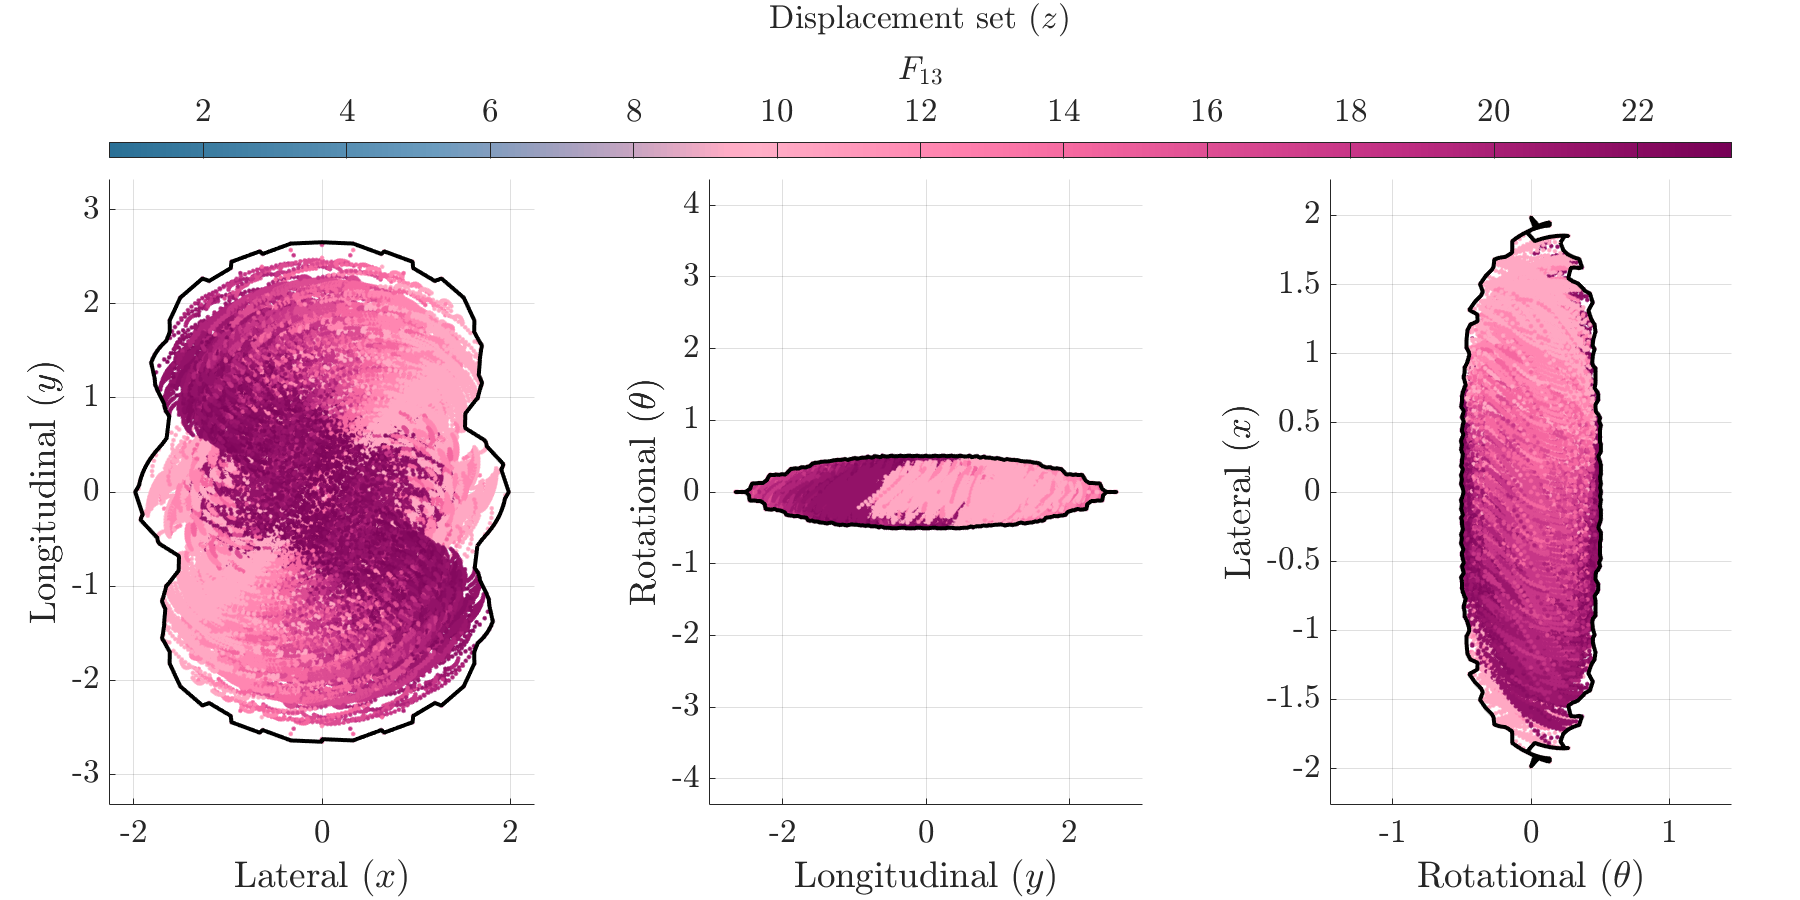

outOfAxisDirn = 'ascend'; % ascend  % descend

% get the levelset values and associated parameters
Fi = repmat(F(1, :), dNumU^4, 1); Fi = Fi(:);
Fj = repmat(F(2, :), dNumU^4, 1); Fj = Fj(:);
FiLimits = [rigidTrot.ithStance.F_inf, ...
            rigidTrot.ithStance.F_sup];
FjLimits = [rigidTrot.jthStance.F_inf, ...
            rigidTrot.jthStance.F_sup];

% plot
fS = 25;
CUB = FRHLstance.p_info.jetDark; % extract the colormap
f = figure('units', 'pixels', 'position', [0 0 1800 900], ...
                'Color','w','Visible','on');
tl = tiledlayout(f, 1, 3, "TileSpacing", "tight", "Padding", "tight");
FoutNow = Fi; dirnOutTxt = ['$$F_{', num2str(rigidTrot.ithStance.cs), '}$$']; 
idxCyclic = 1:3;
for i = 1:3
    idxHorz = idxCyclic(1); zHorzNow = z{idxHorz}(:); dirnHorzTxt = dirnLabelTxt{idxHorz};
        idxVert = idxCyclic(2); zVertNow = z{idxVert}(:); dirnVertTxt = dirnLabelTxt{idxVert};
            idxOut = idxCyclic(3); zOutNow = z{idxOut}(:);
    bound2Dnow = fullyShrunkBoundary2D{i};
    [~, iOut] = sort(zOutNow, 1, outOfAxisDirn); % STILL SORT USING THE OUT-OF-PLANE COMPONENT
    X = linspace(FiLimits(1), FiLimits(2), size(turbo, 1))';
    colNow = interpColorAndCondition(X, CUB, FoutNow);
    ax = nexttile(tl); hold(ax, "on"); grid(ax, "on");
    scatter(ax, zHorzNow(iOut), zVertNow(iOut), 100, colNow(iOut, :), 'Marker', '.');
    plot(ax, zHorzNow(bound2Dnow), zVertNow(bound2Dnow), 'k-', 'LineWidth', 3.0);
    axis(ax, "equal", "padded"); ax.FontSize = fS;
    xlabel(ax, dirnHorzTxt);
    ylabel(ax, dirnVertTxt); 
    colormap(ax, CUB); clim(ax, FiLimits); 
    if strcmp(outOfAxisDirn, 'descend')
        ax.XDir = "reverse";
    end
    idxCyclic = circshift(idxCyclic, -1);
end
cb = colorbar('FontSize', fS); cb.Layout.Tile = "north";
cb.Label.String = dirnOutTxt; cb.Label.Interpreter = "latex";
cb.TickLabelInterpreter = "latex";
title(tl, 'Displacement set ($z$)', 'FontSize', fS, 'Interpreter', 'latex');

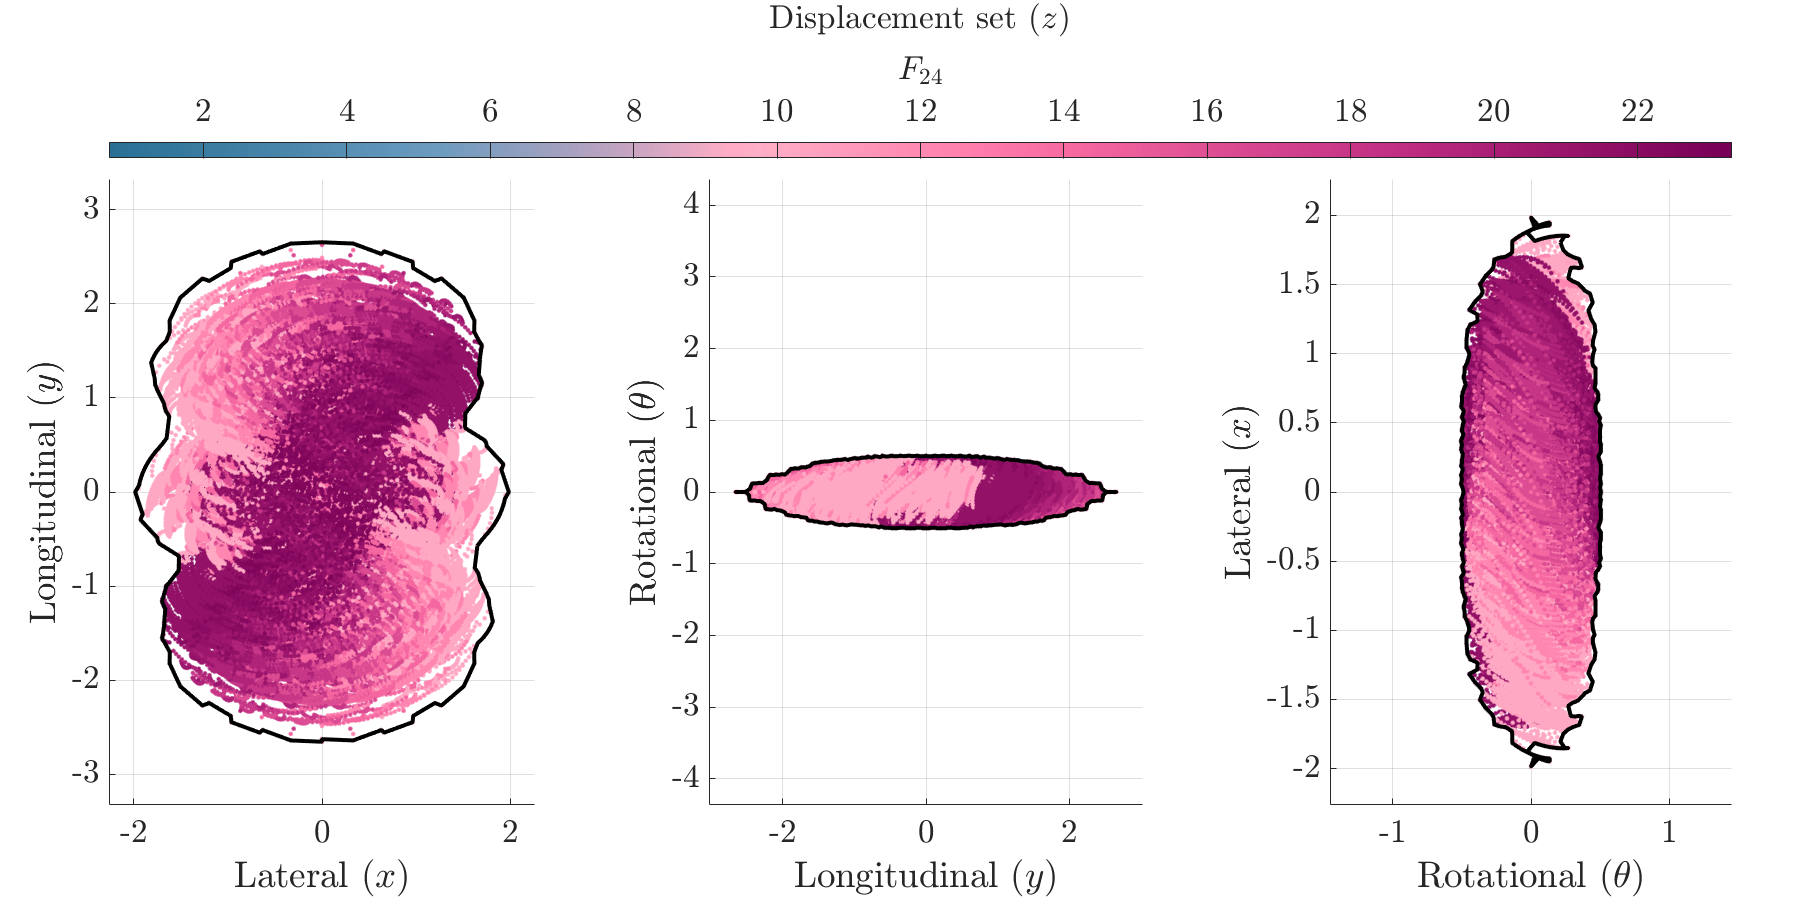


fS = 25;
CUB = FRHLstance.p_info.jetDark; % extract the colormap
f = figure('units', 'pixels', 'position', [0 0 1800 900], ...
                'Color','w','Visible','on');
tl = tiledlayout(f, 1, 3, "TileSpacing", "tight", "Padding", "tight");
FoutNow = Fj; dirnOutTxt = ['$$F_{', num2str(rigidTrot.jthStance.cs), '}$$'];
idxCyclic = 1:3;
for i = 1:3
    idxHorz = idxCyclic(1); zHorzNow = z{idxHorz}(:); dirnHorzTxt = dirnLabelTxt{idxHorz};
        idxVert = idxCyclic(2); zVertNow = z{idxVert}(:); dirnVertTxt = dirnLabelTxt{idxVert};
            idxOut = idxCyclic(3); zOutNow = z{idxOut}(:);
    bound2Dnow = fullyShrunkBoundary2D{i};
    [~, iOut] = sort(zOutNow, 1, outOfAxisDirn);
    X = linspace(FjLimits(1), FjLimits(2), size(turbo, 1))';
    colNow = interpColorAndCondition(X, CUB, FoutNow);
    ax = nexttile(tl); hold(ax, "on"); grid(ax, "on");
    scatter(ax, zHorzNow(iOut), zVertNow(iOut), 100, colNow(iOut, :), 'Marker', '.');
    plot(ax, zHorzNow(bound2Dnow), zVertNow(bound2Dnow), 'k-', 'LineWidth', 3.0);
    axis(ax, "equal", "padded"); ax.FontSize = fS;
    xlabel(ax, dirnHorzTxt);
    ylabel(ax, dirnVertTxt); 
    colormap(ax, CUB); clim(ax, FjLimits);
    if strcmp(outOfAxisDirn, 'descend')
        ax.XDir = "reverse";
    end
    idxCyclic = circshift(idxCyclic, -1);
end
cb = colorbar('FontSize', fS); cb.Layout.Tile = "north";
cb.Label.String = dirnOutTxt; cb.Label.Interpreter = "latex";
cb.TickLabelInterpreter = "latex";
title(tl, 'Displacement set ($z$)', 'FontSize', fS, 'Interpreter', 'latex');

Some test body trajectories at 1.2 integration and path limits.

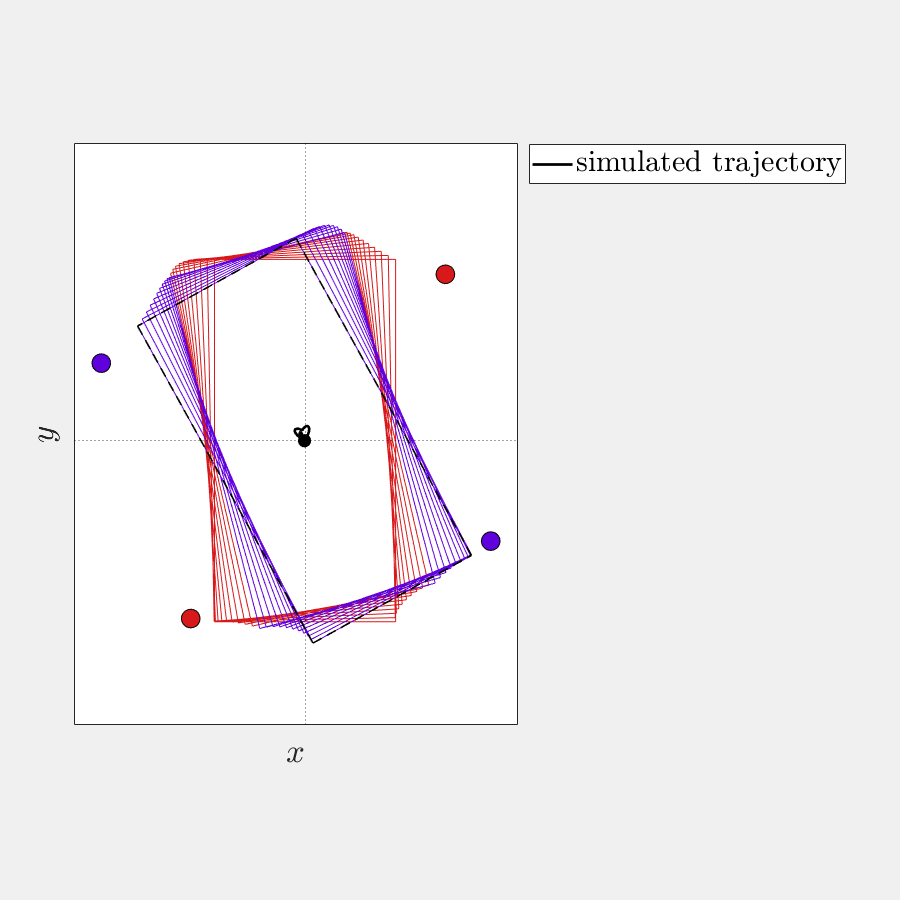

disp = [-0.00591021, -0.00152581, +0.505298]; % ~in place positive (CCW) rotation
[~, i] = min( abs(z{1} - disp(1)) + abs(z{2} - disp(2)) + abs(z{3} - disp(3)), [], "all" );
[iRow, iCol] = ind2sub( size(z{1}), i ); clear i;
inputsI = u(iRow, 1:2); inputsJ = u(iRow, 3:4);
ref = []; 
ref.tOff = 0; ref.T = T{1}; 
ref13 = ref; ref24 = ref;
ref13.P = refPt(1:2, iCol)'; ref24.P = refPt(3:4, iCol)';
ref13.tMax = rigidTrot.stanceSpace.aLimits{1};
ref24.tMax = rigidTrot.stanceSpace.aLimits{2};
[tIC13, tFC13] = altQuadGait.computeSubgaitIntegrationTimes...
               (rigidTrot, ...
               inputsI, ...
               ref13.T, [], ref13.tMax);
[tIC24, tFC24] = altQuadGait.computeSubgaitIntegrationTimes...
               (rigidTrot, ...
               inputsJ, ...
               ref24.T, [], ref24.tMax);
configTraj13 = Path2_Mobility.simulateConfigurationTrajectory...
                                                    (ref13, ...
                                                     [tIC13, tFC13], ...
                                                     rigidTrot.ithStance, ...
                                                     [false, false]); % , ... % plot stance path in both F and panels
                                                     % 'all'); % valid modes: 'all', 'theta'
configTraj24 = Path2_Mobility.simulateConfigurationTrajectory...
                                                    (ref24, ...
                                                     [tIC24, tFC24], ...
                                                     rigidTrot.jthStance, ...
                                                     [false, false]); % , ...
                                                     % 'all');
jointStancePath = altQuadGait.fullCycleConfigTrajectory(rigidTrot, configTraj13, configTraj24, [], false);

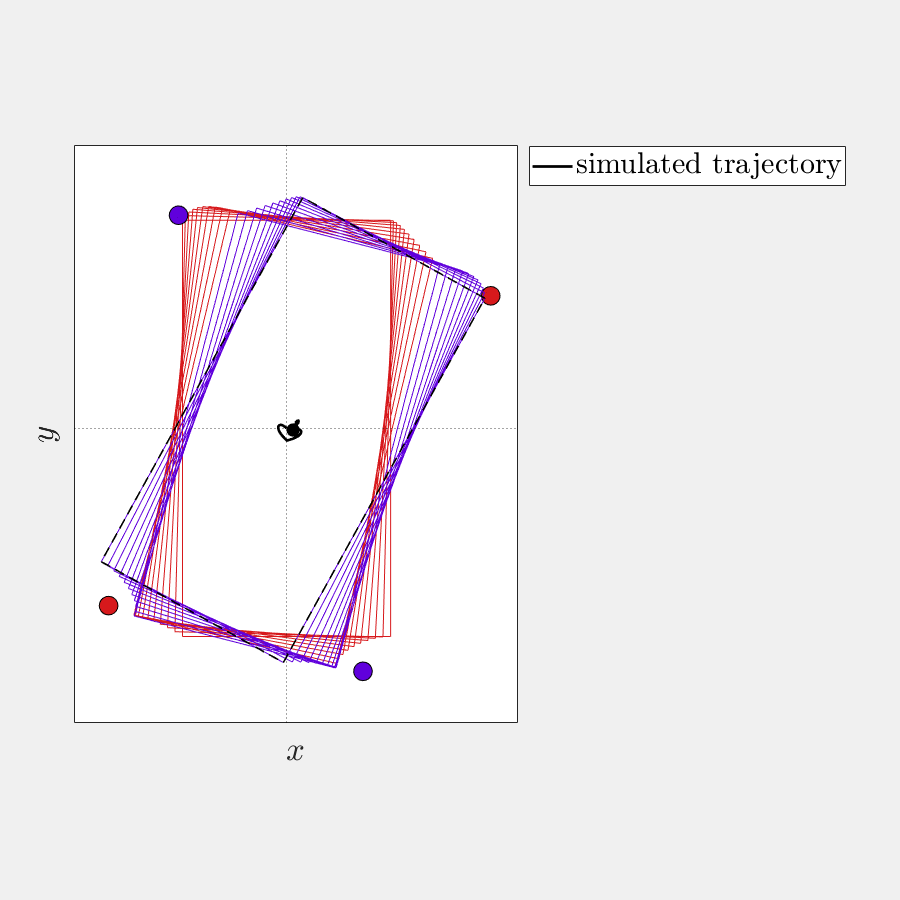

disp = [+0.06224150, -0.01606860, -0.505298]; % ~in place negative ( CW) rotation
[~, i] = min( abs(z{1} - disp(1)) + abs(z{2} - disp(2)) + abs(z{3} - disp(3)), [], "all" );
[iRow, iCol] = ind2sub( size(z{1}), i ); clear i;
inputsI = u(iRow, 1:2); inputsJ = u(iRow, 3:4);
ref = []; 
ref.tOff = 0; ref.T = T{1}; 
ref13 = ref; ref24 = ref;
ref13.P = refPt(1:2, iCol)'; ref24.P = refPt(3:4, iCol)';
ref13.tMax = rigidTrot.stanceSpace.aLimits{1};
ref24.tMax = rigidTrot.stanceSpace.aLimits{2};
[tIC13, tFC13] = altQuadGait.computeSubgaitIntegrationTimes...
               (rigidTrot, ...
               inputsI, ...
               ref13.T, [], ref13.tMax);
[tIC24, tFC24] = altQuadGait.computeSubgaitIntegrationTimes...
               (rigidTrot, ...
               inputsJ, ...
               ref24.T, [], ref24.tMax);
configTraj13 = Path2_Mobility.simulateConfigurationTrajectory...
                                                    (ref13, ...
                                                     [tIC13, tFC13], ...
                                                     rigidTrot.ithStance, ...
                                                     [false, false]); % , ... % plot stance path in both F and panels
                                                     % 'all'); % valid modes: 'all', 'theta'
configTraj24 = Path2_Mobility.simulateConfigurationTrajectory...
                                                    (ref24, ...
                                                     [tIC24, tFC24], ...
                                                     rigidTrot.jthStance, ...
                                                     [false, false]); % , ...
                                                     % 'all');
jointStancePath = altQuadGait.fullCycleConfigTrajectory(rigidTrot, configTraj13, configTraj24, [], false);

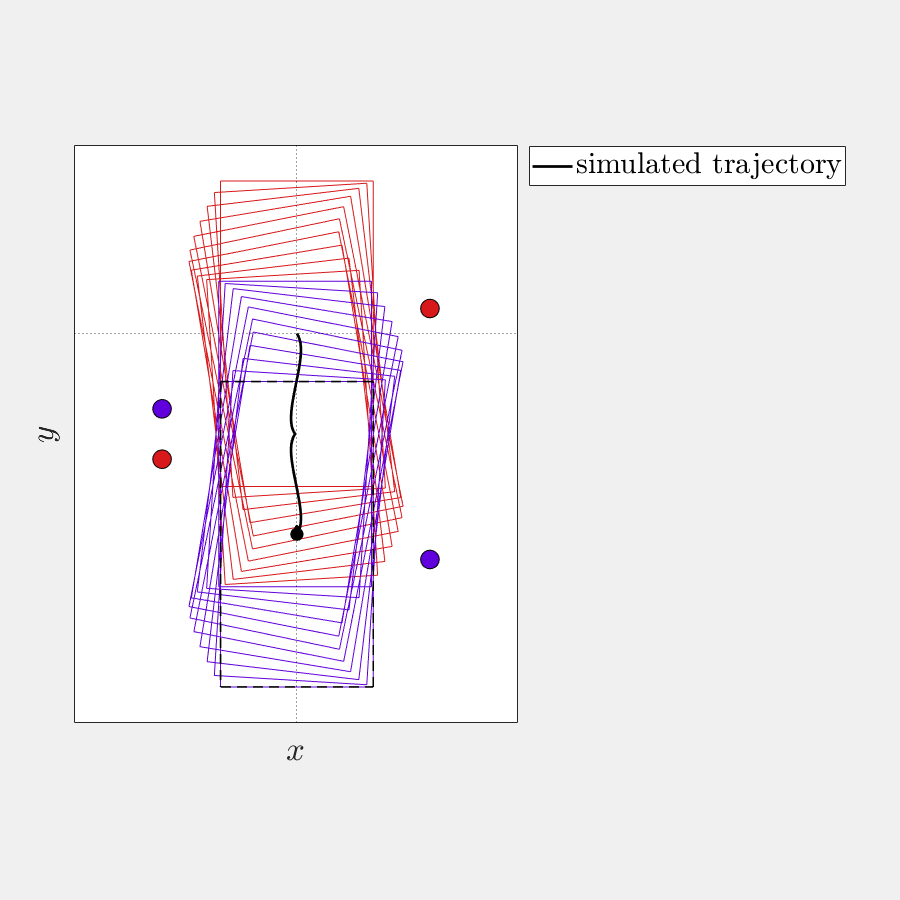

disp = [+0.00000001, -2.62628000, -0.000000]; % maximum backwards (-y) translation
[~, i] = min( abs(z{1} - disp(1)) + abs(z{2} - disp(2)) + abs(z{3} - disp(3)), [], "all" );
[iRow, iCol] = ind2sub( size(z{1}), i ); clear i;
inputsI = u(iRow, 1:2); inputsJ = u(iRow, 3:4);
ref = []; 
ref.tOff = 0; ref.T = T{1}; 
ref13 = ref; ref24 = ref;
ref13.P = refPt(1:2, iCol)'; ref24.P = refPt(3:4, iCol)';
ref13.tMax = rigidTrot.stanceSpace.aLimits{1};
ref24.tMax = rigidTrot.stanceSpace.aLimits{2};
[tIC13, tFC13] = altQuadGait.computeSubgaitIntegrationTimes...
               (rigidTrot, ...
               inputsI, ...
               ref13.T, [], ref13.tMax);
[tIC24, tFC24] = altQuadGait.computeSubgaitIntegrationTimes...
               (rigidTrot, ...
               inputsJ, ...
               ref24.T, [], ref24.tMax);
configTraj13 = Path2_Mobility.simulateConfigurationTrajectory...
                                                    (ref13, ...
                                                     [tIC13, tFC13], ...
                                                     rigidTrot.ithStance, ...
                                                     [false, false]); % , ... % plot stance path in both F and panels
                                                     % 'all'); % valid modes: 'all', 'theta'
configTraj24 = Path2_Mobility.simulateConfigurationTrajectory...
                                                    (ref24, ...
                                                     [tIC24, tFC24], ...
                                                     rigidTrot.jthStance, ...
                                                     [false, false]); % , ...
                                                     % 'all');
jointStancePath = altQuadGait.fullCycleConfigTrajectory(rigidTrot, configTraj13, configTraj24, [], false);

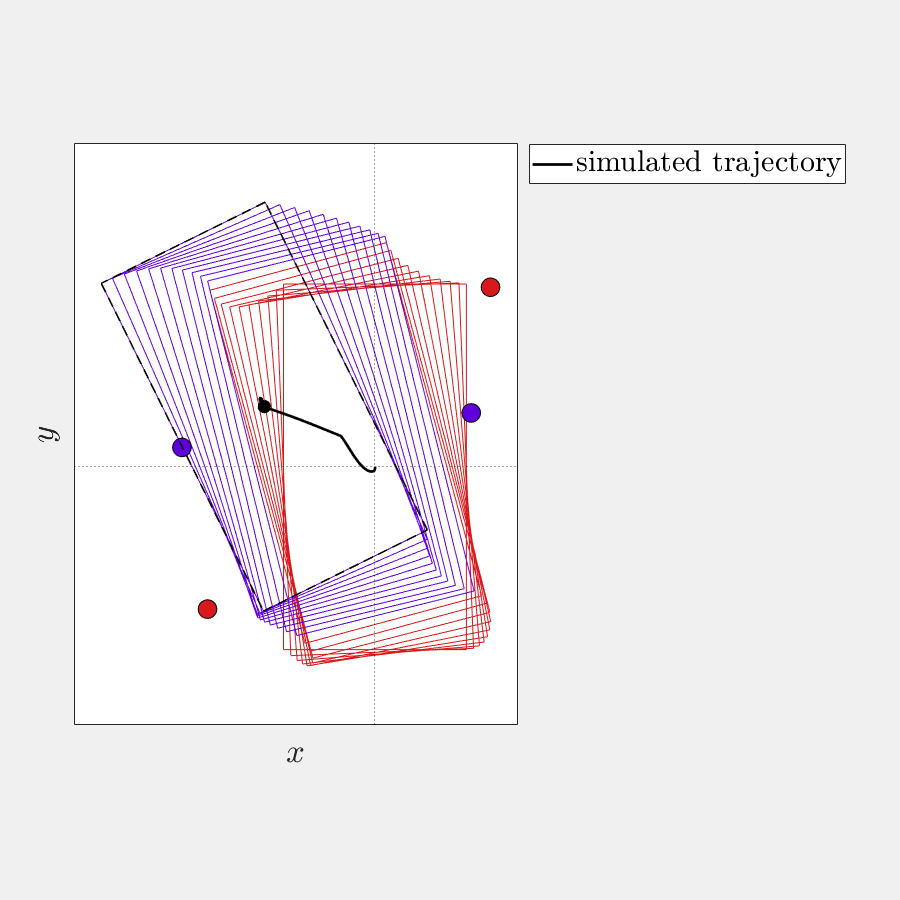

disp = [-1.20972000, +0.65847800, +0.459602]; % FL-course with positive (CCW) rotation
[~, i] = min( abs(z{1} - disp(1)) + abs(z{2} - disp(2)) + abs(z{3} - disp(3)), [], "all" );
[iRow, iCol] = ind2sub( size(z{1}), i ); clear i;
inputsI = u(iRow, 1:2); inputsJ = u(iRow, 3:4);
ref = []; 
ref.tOff = 0; ref.T = T{1}; 
ref13 = ref; ref24 = ref;
ref13.P = refPt(1:2, iCol)'; ref24.P = refPt(3:4, iCol)';
ref13.tMax = rigidTrot.stanceSpace.aLimits{1};
ref24.tMax = rigidTrot.stanceSpace.aLimits{2};
[tIC13, tFC13] = altQuadGait.computeSubgaitIntegrationTimes...
               (rigidTrot, ...
               inputsI, ...
               ref13.T, [], ref13.tMax);
[tIC24, tFC24] = altQuadGait.computeSubgaitIntegrationTimes...
               (rigidTrot, ...
               inputsJ, ...
               ref24.T, [], ref24.tMax);
configTraj13 = Path2_Mobility.simulateConfigurationTrajectory...
                                                    (ref13, ...
                                                     [tIC13, tFC13], ...
                                                     rigidTrot.ithStance, ...
                                                     [false, false]); % , ... % plot stance path in both F and panels
                                                     % 'all'); % valid modes: 'all', 'theta'
configTraj24 = Path2_Mobility.simulateConfigurationTrajectory...
                                                    (ref24, ...
                                                     [tIC24, tFC24], ...
                                                     rigidTrot.jthStance, ...
                                                     [false, false]); % , ...
                                                     % 'all');
jointStancePath = altQuadGait.fullCycleConfigTrajectory(rigidTrot, configTraj13, configTraj24, [], false);

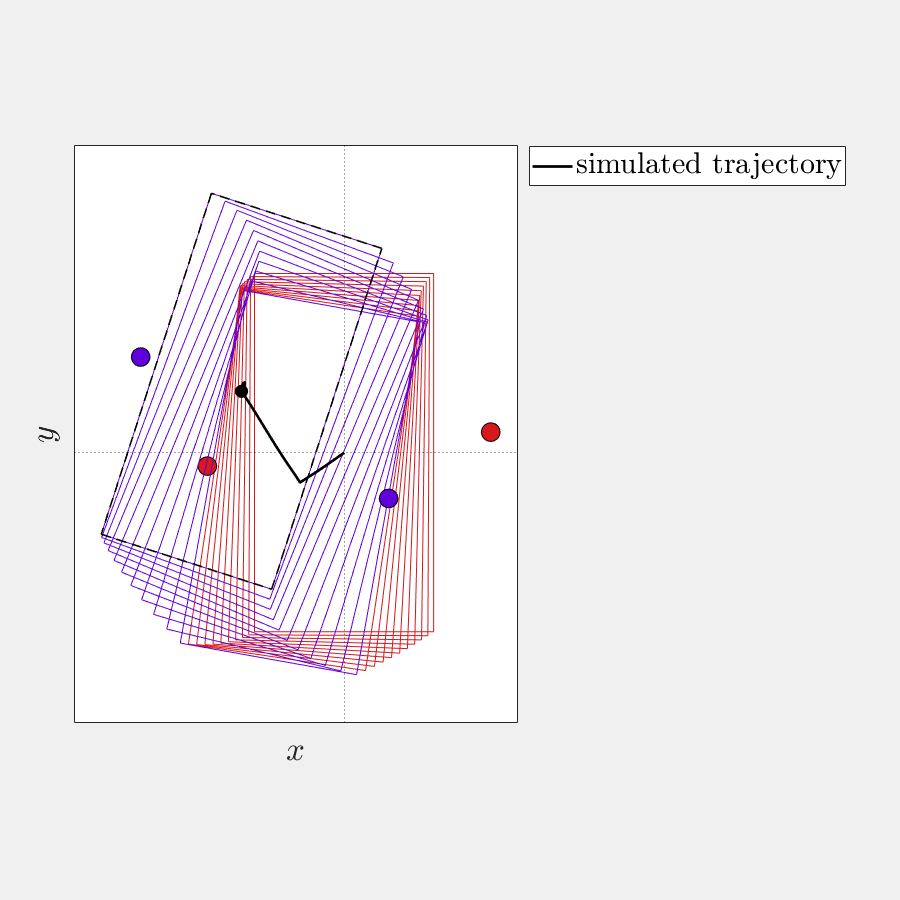

disp = [-1.14538000, +0.68484000, -0.312413]; % FL-course with negative (CCW) rotation
[~, i] = min( abs(z{1} - disp(1)) + abs(z{2} - disp(2)) + abs(z{3} - disp(3)), [], "all" );
[iRow, iCol] = ind2sub( size(z{1}), i ); clear i;
inputsI = u(iRow, 1:2); inputsJ = u(iRow, 3:4);
ref = []; 
ref.tOff = 0; ref.T = T{1}; 
ref13 = ref; ref24 = ref;
ref13.P = refPt(1:2, iCol)'; ref24.P = refPt(3:4, iCol)';
ref13.tMax = rigidTrot.stanceSpace.aLimits{1};
ref24.tMax = rigidTrot.stanceSpace.aLimits{2};
[tIC13, tFC13] = altQuadGait.computeSubgaitIntegrationTimes...
               (rigidTrot, ...
               inputsI, ...
               ref13.T, [], ref13.tMax);
[tIC24, tFC24] = altQuadGait.computeSubgaitIntegrationTimes...
               (rigidTrot, ...
               inputsJ, ...
               ref24.T, [], ref24.tMax);
configTraj13 = Path2_Mobility.simulateConfigurationTrajectory...
                                                    (ref13, ...
                                                     [tIC13, tFC13], ...
                                                     rigidTrot.ithStance, ...
                                                     [false, false]); % , ... % plot stance path in both F and panels
                                                     % 'all'); % valid modes: 'all', 'theta'
configTraj24 = Path2_Mobility.simulateConfigurationTrajectory...
                                                    (ref24, ...
                                                     [tIC24, tFC24], ...
                                                     rigidTrot.jthStance, ...
                                                     [false, false]); % , ...
                                                     % 'all');
jointStancePath = altQuadGait.fullCycleConfigTrajectory(rigidTrot, configTraj13, configTraj24, [], false);

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
        dataMobilityFull = 'Data\HAMR6_SE2_kinematicMobility_full.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
        dataMobilityFull = 'Data\case_1_kinematicMobility_full.mat';
end
if exist(dataName, "file")
    load(dataName);
else
    error(['ERROR! The base kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx".']);
end
if exist(dataMotPlanName, "file")
    load(dataMotPlanName);
else
    error(['ERROR! The motion planning kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx" (last section).']);
end

## Effect of limb length

Here, we perform the same experiments, but explore the effect of changing the limb length.

% number of body morphing points
numPts = 5;

% limb length ratios to iterate over
na = linspace(0.2, 1, numPts);

% iterate and compute the MOBILITY
% ... init stuff for later
FRHLstance = cell(1, numPts); FLHRstance = cell(1, numPts); 
rigidTrot = cell(1, numPts);
refPt = cell(1, numPts); 
F = refPt; u = F; 
zX = F; zY = F; zYaw = F; Ex = F; Ey = F; Eyaw = F;
tic;
for iP = 1:numel(na)
    submanifoldIndex = 5;
    integrationTime = 1.2*ones(1, 2);
    refPtOrg = zeros(1, 2); % main ref pt to construct perp coords
    FRHLstance{iP} = Path2_Mobility(submanifoldIndex, ...
                        kin, kinfunc, p_kin, p_info, ...
                        integrationTime, refPtOrg, ...
                        'NoPhaseLimits', 'branched');
    FLHRstance{iP} = Path2_Mobility.constructComplementaryStance...
                        (FRHLstance{iP}, ...
                        kin, kinfunc, p_kin, p_info, ...
                        integrationTime, refPtOrg, ...
                        'NoPhaseLimits', 'branched');
    FRHLstance{iP} = Path2_Mobility.changeLimbRatio(FRHLstance{iP}, na(iP));
    FLHRstance{iP} = Path2_Mobility.changeLimbRatio(FLHRstance{iP}, na(iP));
    dNumU = 11;
    dNumLeaves = 11;
    rigidTrot{iP} = altQuadGait(FRHLstance{iP}, FLHRstance{iP}, ...
        "multi-F-levelsets", ...
        "path_limit_compliant", ...
        [-1.2, 1.2], fh2_b__i, dNumU);
    T = repmat({-1.2*ones(1, 2)}, 1, 2);
    rigidTrot{iP} = altQuadGait.generateInputSpace( rigidTrot{iP}, dNumU, T );
    rigidTrot{iP} = altQuadGait.simulateInputSpace( rigidTrot{iP} );
    rigidTrot{iP} = altQuadGait.computeGaitCost( rigidTrot{iP} );
    rigidTrot{iP} = altQuadGait.computeMobility(rigidTrot{iP}, 'sim');
    [refPt{iP}, F{iP}, u{iP}, ~, zX{iP}, zY{iP}, zYaw{iP}, Ex{iP}, Ey{iP}, Eyaw{iP}] = ...
                altQuadGait.flattenMobilityStructs(rigidTrot{iP}, 'sim');
end
toc;

Elapsed time is 149.342857 seconds.


% obtain boundaries and other information for plotting the 3D reachability
% and mobility sets, and their 2D projections
tic;
z = cell(1, numPts); zx = z; zy = z; zyaw = z;
Evel = z; EvelX = z; EvelY = z; EvelYaw = z;
Eaccln = z; EacclnX = z; EacclnY = z; EacclnYaw = z;
fullyShrunkBoundary3D = z; fullyShrunkBoundary2D = z;
fullyShrunkBoundary3D_Evel = z; fullyShrunkBoundary2D_Evel = z;
fullyShrunkBoundary3D_Eaccln = z; fullyShrunkBoundary2D_Eaccln = z;

for iP = 1:numPts
    z{iP} = {zX{iP}, zY{iP}, zYaw{iP}};
    zx{iP} = z{iP}{1}(:); zy{iP} = z{iP}{2}(:); zyaw{iP} = z{iP}{3}(:);

    Evel{iP} = {Ex{iP}.vel, Ey{iP}.vel, Eyaw{iP}.vel};
    EvelX{iP} = Evel{iP}{1}(:); EvelY{iP} = Evel{iP}{2}(:); EvelYaw{iP} = Evel{iP}{3}(:);

    Eaccln{iP} = {Ex{iP}.accln, Ey{iP}.accln, Eyaw{iP}.accln};
    EacclnX{iP} = Eaccln{iP}{1}(:); EacclnY{iP} = Eaccln{iP}{2}(:); EacclnYaw{iP} = Eaccln{iP}{3}(:);
    
    idxCyclic = 1:3;

    fullyShrunkBoundary3D{iP} = boundary(zx{iP}, zy{iP}, zyaw{iP}, 1);
    fullyShrunkBoundary2D{iP} = cell(1, 3); 
    for j = 1:3
        fullyShrunkBoundary2D{iP}{j} = boundary(z{iP}{idxCyclic(1)}(:), z{iP}{idxCyclic(2)}(:), 1);
        idxCyclic = circshift(idxCyclic, -1);
    end

    fullyShrunkBoundary3D_Evel{iP} = boundary(EvelX{iP}, EvelY{iP}, EvelYaw{iP}, 1);
    fullyShrunkBoundary2D_Evel{iP} = cell(1, 3); idxCyclic = 1:3;
    for j = 1:3
        fullyShrunkBoundary2D_Evel{iP}{j} = boundary(Evel{iP}{idxCyclic(1)}(:), Evel{iP}{idxCyclic(2)}(:), 1);
        idxCyclic = circshift(idxCyclic, -1);
    end

    fullyShrunkBoundary3D_Eaccln{iP} = boundary(EacclnX{iP}, EacclnY{iP}, EacclnYaw{iP}, 1);
    fullyShrunkBoundary2D_Eaccln{iP} = cell(1, 3); idxCyclic = 1:3;
    for j = 1:3
        fullyShrunkBoundary2D_Eaccln{iP}{j} = boundary(Eaccln{iP}{idxCyclic(1)}(:), Eaccln{iP}{idxCyclic(2)}(:), 1);
        idxCyclic = circshift(idxCyclic, -1);
    end
    if iP == 1
        dirnLabelTxt = {'Lateral ($x$)', 'Longitudinal ($y$)', 'Rotational ($\theta$)'};
    end
end
toc;

Elapsed time is 1527.005674 seconds.


set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

pltFlag = 'off'; % on % off

for iP = 1:numPts


    % 3D bounds of reachable and mobility sets
    fS = 25; panelFaceColor = 99/255*ones(1, 3);
    figure('units', 'pixels', 'position', [0 0 900 900], ...
                    'Color','w','Visible',pltFlag); ax = gca;
    trisurf(fullyShrunkBoundary3D{iP}, zX{iP}, zY{iP}, zYaw{iP}, ...
        'LineWidth', 0.1, 'LineStyle', '-', 'FaceColor', panelFaceColor);
    axis(ax, "equal", "padded"); ax.FontSize = fS; title(ax, 'Displacement set ($z$)');
    xlabel(ax, dirnLabelTxt{1}); ylabel(ax, dirnLabelTxt{2}); zlabel(ax, dirnLabelTxt{3});
    
    fS = 25; panelFaceColor = [31,120,180]/255;
    figure('units', 'pixels', 'position', [0 0 900 900], ...
                    'Color','w','Visible',pltFlag); ax = gca;
    trisurf(fullyShrunkBoundary3D_Evel{iP}, EvelX{iP}, EvelY{iP}, EvelYaw{iP}, ...
        'LineWidth', 0.1, 'LineStyle', '-', 'FaceColor', panelFaceColor);
    axis(ax, "equal", "padded"); ax.FontSize = fS; title(ax, 'Mobility (shape velocity) set ($E$)');
    xlabel(ax, dirnLabelTxt{1}); ylabel(ax, dirnLabelTxt{2}); zlabel(ax, dirnLabelTxt{3});
    
    fS = 25; panelFaceColor = [51,160,44]/255;
    figure('units', 'pixels', 'position', [0 0 900 900], ...
                    'Color','w','Visible',pltFlag); ax = gca;
    trisurf(fullyShrunkBoundary3D_Eaccln{iP}, EacclnX{iP}, EacclnY{iP}, EacclnYaw{iP}, ...
        'LineWidth', 0.1, 'LineStyle', '-', 'FaceColor', panelFaceColor);
    axis(ax, "equal", "padded"); ax.FontSize = fS; title(ax, 'Mobility (shape acceleration) set ($E$)');
    xlabel(ax, dirnLabelTxt{1}); ylabel(ax, dirnLabelTxt{2}); zlabel(ax, dirnLabelTxt{3});
    
    % 2D projections
    
    outOfAxisDirn = 'descend'; % ascend  % descend
    
    fS = 25;
    f = figure('units', 'pixels', 'position', [0 0 1800 900], ...
                    'Color','w','Visible',pltFlag);
    tl = tiledlayout(f, 1, 3, "TileSpacing", "tight", "Padding", "tight");
    idxCyclic = 1:3;
    for i = 1:3
        idxHorz = idxCyclic(1); zHorzNow = z{iP}{idxHorz}(:); dirnHorzTxt = dirnLabelTxt{idxHorz};
            idxVert = idxCyclic(2); zVertNow = z{iP}{idxVert}(:); dirnVertTxt = dirnLabelTxt{idxVert};
                idxOut = idxCyclic(3); zOutNow = z{iP}{idxOut}(:); dirnOutTxt = dirnLabelTxt{idxOut};       
        bound2Dnow = fullyShrunkBoundary2D{iP}{i};
        [~, iOut] = sort(zOutNow, 1, outOfAxisDirn);
        cLimNow = [min(zOutNow), max(zOutNow)];
        X = linspace(cLimNow(1), cLimNow(2), size(turbo, 1))';
        colNow = interpColorAndCondition(X, turbo, zOutNow);
        ax = nexttile(tl); hold(ax, "on"); grid(ax, "on");
        scatter(ax, zHorzNow(iOut), zVertNow(iOut), 100, colNow(iOut, :), 'Marker', '.');
        plot(ax, zHorzNow(bound2Dnow), zVertNow(bound2Dnow), 'k-', 'LineWidth', 3.0);
        axis(ax, "equal", "padded"); ax.FontSize = fS;
        xlabel(ax, dirnHorzTxt);
        ylabel(ax, dirnVertTxt); 
        colormap(ax, "turbo"); clim(ax, cLimNow); 
        cb = colorbar(ax, "northoutside", 'FontSize', fS); 
        cb.Label.String = dirnOutTxt; cb.Label.Interpreter = "latex";
        cb.TickLabelInterpreter = "latex";
        if strcmp(outOfAxisDirn, 'descend')
            ax.XDir = "reverse";
        end
        idxCyclic = circshift(idxCyclic, -1);
    end
    title(tl, 'Displacement set ($z$)', 'FontSize', fS, 'Interpreter', 'latex');
    
    fS = 25;
    f = figure('units', 'pixels', 'position', [0 0 1800 900], ...
                    'Color','w','Visible',pltFlag);
    tl = tiledlayout(f, 1, 3, "TileSpacing", "tight", "Padding", "tight");
    idxCyclic = 1:3;
    for i = 1:3
        idxHorz = idxCyclic(1); zHorzNow = Evel{iP}{idxHorz}(:); dirnHorzTxt = dirnLabelTxt{idxHorz};
            idxVert = idxCyclic(2); zVertNow = Evel{iP}{idxVert}(:); dirnVertTxt = dirnLabelTxt{idxVert};
                idxOut = idxCyclic(3); zOutNow = Evel{iP}{idxOut}(:); dirnOutTxt = dirnLabelTxt{idxOut};       
        bound2Dnow = fullyShrunkBoundary2D_Evel{iP}{i};
        [~, iOut] = sort(zOutNow, 1, outOfAxisDirn);
        cLimNow = [min(zOutNow), max(zOutNow)];
        X = linspace(cLimNow(1), cLimNow(2), size(turbo, 1))';
        colNow = interpColorAndCondition(X, turbo, zOutNow);
        ax = nexttile(tl); hold(ax, "on"); grid(ax, "on");
        scatter(ax, zHorzNow(iOut), zVertNow(iOut), 100, colNow(iOut, :), 'Marker', '.');
        plot(ax, zHorzNow(bound2Dnow), zVertNow(bound2Dnow), 'k-', 'LineWidth', 3.0);
        axis(ax, "equal", "padded"); ax.FontSize = fS;
        xlabel(ax, dirnHorzTxt);
        ylabel(ax, dirnVertTxt); 
        colormap(ax, "turbo"); clim(ax, cLimNow); 
        cb = colorbar(ax, "northoutside", 'FontSize', fS); 
        cb.Label.String = dirnOutTxt; cb.Label.Interpreter = "latex";
        cb.TickLabelInterpreter = "latex";
        if strcmp(outOfAxisDirn, 'descend')
            ax.XDir = "reverse";
        end
        idxCyclic = circshift(idxCyclic, -1);
    end
    title(tl, 'Velocity Mobility set ($E_v$)', 'FontSize', fS, 'Interpreter', 'latex');
    
    fS = 25;
    f = figure('units', 'pixels', 'position', [0 0 1800 900], ...
                    'Color','w','Visible',pltFlag);
    tl = tiledlayout(f, 1, 3, "TileSpacing", "tight", "Padding", "tight");
    idxCyclic = 1:3;
    for i = 1:3
        idxHorz = idxCyclic(1); zHorzNow = Eaccln{iP}{idxHorz}(:); dirnHorzTxt = dirnLabelTxt{idxHorz};
            idxVert = idxCyclic(2); zVertNow = Eaccln{iP}{idxVert}(:); dirnVertTxt = dirnLabelTxt{idxVert};
                idxOut = idxCyclic(3); zOutNow = Eaccln{iP}{idxOut}(:); dirnOutTxt = dirnLabelTxt{idxOut};       
        bound2Dnow = fullyShrunkBoundary2D_Eaccln{iP}{i};
        [~, iOut] = sort(zOutNow, 1, outOfAxisDirn);
        cLimNow = [min(zOutNow), max(zOutNow)];
        X = linspace(cLimNow(1), cLimNow(2), size(turbo, 1))';
        colNow = interpColorAndCondition(X, turbo, zOutNow);
        ax = nexttile(tl); hold(ax, "on"); grid(ax, "on");
        scatter(ax, zHorzNow(iOut), zVertNow(iOut), 100, colNow(iOut, :), 'Marker', '.');
        plot(ax, zHorzNow(bound2Dnow), zVertNow(bound2Dnow), 'k-', 'LineWidth', 3.0);
        axis(ax, "equal", "padded"); ax.FontSize = fS;
        xlabel(ax, dirnHorzTxt);
        ylabel(ax, dirnVertTxt); 
        colormap(ax, "turbo"); clim(ax, cLimNow); 
        cb = colorbar(ax, "northoutside", 'FontSize', fS); 
        cb.Label.String = dirnOutTxt; cb.Label.Interpreter = "latex";
        cb.TickLabelInterpreter = "latex";
        if strcmp(outOfAxisDirn, 'descend')
            ax.XDir = "reverse";
        end
        idxCyclic = circshift(idxCyclic, -1);
    end
    title(tl, 'Acceleration Mobility set ($E_a$)', 'FontSize', fS, 'Interpreter', 'latex');
    
    % 2D projections with F-values
    
    Fi = repmat(F{iP}(1, :), dNumU^4, 1); Fi = Fi(:);
    Fj = repmat(F{iP}(2, :), dNumU^4, 1); Fj = Fj(:);
    FiLimits = [rigidTrot{iP}.ithStance.F_inf, ...
                rigidTrot{iP}.ithStance.F_sup];
    FjLimits = [rigidTrot{iP}.jthStance.F_inf, ...
                rigidTrot{iP}.jthStance.F_sup];
    
    fS = 25;
    CUB = rigidTrot{iP}.ithStance.p_info.jetDark;
    f = figure('units', 'pixels', 'position', [0 0 1800 900], ...
                    'Color','w','Visible',pltFlag);
    tl = tiledlayout(f, 1, 3, "TileSpacing", "tight", "Padding", "tight");
    FoutNow = Fi; dirnOutTxt = ['$$F_{', num2str(rigidTrot{iP}.ithStance.cs), '}$$']; 
    idxCyclic = 1:3;
    for i = 1:3
        idxHorz = idxCyclic(1); zHorzNow = z{iP}{idxHorz}(:); dirnHorzTxt = dirnLabelTxt{idxHorz};
            idxVert = idxCyclic(2); zVertNow = z{iP}{idxVert}(:); dirnVertTxt = dirnLabelTxt{idxVert};
                idxOut = idxCyclic(3); zOutNow = z{iP}{idxOut}(:);
        bound2Dnow = fullyShrunkBoundary2D{iP}{i};
        [~, iOut] = sort(zOutNow, 1, outOfAxisDirn);
        X = linspace(FiLimits(1), FiLimits(2), size(turbo, 1))';
        colNow = interpColorAndCondition(X, CUB, FoutNow);
        ax = nexttile(tl); hold(ax, "on"); grid(ax, "on");
        scatter(ax, zHorzNow(iOut), zVertNow(iOut), 100, colNow(iOut, :), 'Marker', '.');
        plot(ax, zHorzNow(bound2Dnow), zVertNow(bound2Dnow), 'k-', 'LineWidth', 3.0);
        axis(ax, "equal", "padded"); ax.FontSize = fS;
        xlabel(ax, dirnHorzTxt);
        ylabel(ax, dirnVertTxt); 
        colormap(ax, CUB); clim(ax, FiLimits); 
        if strcmp(outOfAxisDirn, 'descend')
            ax.XDir = "reverse";
        end
        idxCyclic = circshift(idxCyclic, -1);
    end
    cb = colorbar('FontSize', fS); cb.Layout.Tile = "north";
    cb.Label.String = dirnOutTxt; cb.Label.Interpreter = "latex";
    cb.TickLabelInterpreter = "latex";
    title(tl, 'Displacement set ($z$)', 'FontSize', fS, 'Interpreter', 'latex');
    
    fS = 25;
    CUB = rigidTrot{iP}.ithStance.p_info.jetDark;
    f = figure('units', 'pixels', 'position', [0 0 1800 900], ...
                    'Color','w','Visible',pltFlag);
    tl = tiledlayout(f, 1, 3, "TileSpacing", "tight", "Padding", "tight");
    FoutNow = Fj; dirnOutTxt = ['$$F_{', num2str(rigidTrot{iP}.jthStance.cs), '}$$'];
    idxCyclic = 1:3;
    for i = 1:3
        idxHorz = idxCyclic(1); zHorzNow = z{iP}{idxHorz}(:); dirnHorzTxt = dirnLabelTxt{idxHorz};
            idxVert = idxCyclic(2); zVertNow = z{iP}{idxVert}(:); dirnVertTxt = dirnLabelTxt{idxVert};
                idxOut = idxCyclic(3); zOutNow = z{iP}{idxOut}(:);
        bound2Dnow = fullyShrunkBoundary2D{iP}{i};
        [~, iOut] = sort(zOutNow, 1, outOfAxisDirn);
        X = linspace(FjLimits(1), FjLimits(2), size(turbo, 1))';
        colNow = interpColorAndCondition(X, CUB, FoutNow);
        ax = nexttile(tl); hold(ax, "on"); grid(ax, "on");
        scatter(ax, zHorzNow(iOut), zVertNow(iOut), 100, colNow(iOut, :), 'Marker', '.');
        plot(ax, zHorzNow(bound2Dnow), zVertNow(bound2Dnow), 'k-', 'LineWidth', 3.0);
        axis(ax, "equal", "padded"); ax.FontSize = fS;
        xlabel(ax, dirnHorzTxt);
        ylabel(ax, dirnVertTxt); 
        colormap(ax, CUB); clim(ax, FjLimits);
        if strcmp(outOfAxisDirn, 'descend')
            ax.XDir = "reverse";
        end
        idxCyclic = circshift(idxCyclic, -1);
    end
    cb = colorbar('FontSize', fS); cb.Layout.Tile = "north";
    cb.Label.String = dirnOutTxt; cb.Label.Interpreter = "latex";
    cb.TickLabelInterpreter = "latex";
    title(tl, 'Displacement set ($z$)', 'FontSize', fS, 'Interpreter', 'latex');
    
end

if strcmp(pltFlag, 'off')
    close all; clc;
end

Collect the set occupancy data and plot it for our analysis.

zxLim = cell(1, numPts); zyLim = zxLim; zyawLim = zxLim; zP2P = nan(3, numPts); zSetAnis = zP2P(1, :);
EvxLim = cell(1, numPts); EvyLim = EvxLim; EvyawLim = EvxLim; EvP2P = nan(3, numPts); EvSetAnis = EvP2P(1, :);
EaxLim = cell(1, numPts); EayLim = EaxLim; EayawLim = EaxLim; EaP2P = nan(3, numPts); EaSetAnis = EaP2P(1, :);
for iP = 1:numPts
    zxLim{iP} = [min(zx{iP}), max(zx{iP})];
    zyLim{iP} = [min(zy{iP}), max(zy{iP})];
    zyawLim{iP} = [min(zyaw{iP}), max(zyaw{iP})];
    zP2P(:, iP) = [ diff(zxLim{iP});
                    diff(zyLim{iP});
                    diff(zyawLim{iP}) ];
    zSetAnis(iP) = diff(zyLim{iP})/diff(zxLim{iP});
    
    EvxLim{iP} = [min(EvelX{iP}), max(EvelX{iP})];
    EvyLim{iP} = [min(EvelY{iP}), max(EvelY{iP})];
    EvyawLim{iP} = [min(EvelYaw{iP}), max(EvelYaw{iP})];
    EvP2P(:, iP) = [ diff(EvxLim{iP});
                     diff(EvyLim{iP});
                     diff(EvyawLim{iP}) ];
    EvSetAnis(iP) = diff(EvyLim{iP})/diff(EvxLim{iP});
    
    EaxLim{iP} = [min(EacclnX{iP}), max(EacclnX{iP})];
    EayLim{iP} = [min(EacclnY{iP}), max(EacclnY{iP})];
    EayawLim{iP} = [min(EacclnYaw{iP}), max(EacclnYaw{iP})];
    EaP2P(:, iP) = [ diff(EaxLim{iP});
                     diff(EayLim{iP});
                     diff(EayawLim{iP}) ];
    EaSetAnis(iP) = diff(EayLim{iP})/diff(EaxLim{iP}); 
end

Set occupancy plots for the reachable set, velocity-based mobility set, and acceleration-based mobility set.

pltFlag = 'off'; % on % off

fS = 25;
f = figure('units', 'pixels', 'position', [0 0 1800 900], ...
                'Color','w','Visible', pltFlag);
tl = tiledlayout(f, 1, 3, "TileSpacing", "tight", "Padding", "tight");
yLabelTxt = dirnLabelTxt;
for i = 1:3
    ax = nexttile(tl); hold(ax, "on"); grid(ax, "on");
    plot(ax, na, zP2P(i, :), 'k-', 'LineWidth', 3.0);
    axis(ax, "padded"); ax.FontSize = fS;
    xlim(ax, [na(1) na(end)]);
    ylabel(ax, yLabelTxt{i}); 
end
xlabel(tl, 'Limb length ratio ($a$)', 'FontSize', fS, 'Interpreter', 'latex');
title (tl, 'Variation in peak-to-peak displacement',  'FontSize', fS, 'Interpreter', 'latex');

fS = 25;
f = figure('units', 'pixels', 'position', [0 0 1800 900], ...
                'Color','w','Visible', pltFlag);
tl = tiledlayout(f, 1, 3, "TileSpacing", "tight", "Padding", "tight");
yLabelTxt = dirnLabelTxt;
for i = 1:3
    ax = nexttile(tl); hold(ax, "on"); grid(ax, "on");
    plot(ax, na, EvP2P(i, :), 'k-', 'LineWidth', 3.0);
    axis(ax, "padded"); ax.FontSize = fS;
    xlim(ax, [na(1) na(end)]);
    ylabel(ax, yLabelTxt{i}); 
end
xlabel(tl, 'Limb length ratio ($a$)', 'FontSize', fS, 'Interpreter', 'latex');
title (tl, 'Variation in peak-to-peak velocity mobility',  'FontSize', fS, 'Interpreter', 'latex');

fS = 25;
f = figure('units', 'pixels', 'position', [0 0 1800 900], ...
                'Color','w','Visible', pltFlag);
tl = tiledlayout(f, 1, 3, "TileSpacing", "tight", "Padding", "tight");
yLabelTxt = dirnLabelTxt;
for i = 1:3
    ax = nexttile(tl); hold(ax, "on"); grid(ax, "on");
    plot(ax, na, EaP2P(i, :), 'k-', 'LineWidth', 3.0);
    axis(ax, "padded"); ax.FontSize = fS;
    xlim(ax, [na(1) na(end)]);
    ylabel(ax, yLabelTxt{i}); 
end
xlabel(tl, 'Limb length ratio ($a$)', 'FontSize', fS, 'Interpreter', 'latex');
title (tl, 'Variation in peak-to-peak acceleration mobility',  'FontSize', fS, 'Interpreter', 'latex');

if strcmp(pltFlag, 'off')
    close all; clc;
end

Evolution of the translational anisotropy.

pltFlag = 'off'; % on % off

fS = 25;
figure('units', 'pixels', 'position', [0 0 1800 900], ...
                'Color','w','Visible', pltFlag);
ax = gca; hold(ax, "on"); grid(ax, "on");
plot(ax, na, zSetAnis, 'k-', 'LineWidth', 3.0);
yline(ax, 1, 'k:', 'LineWidth', 1.2, ...
    'Label', 'Equally good at lateral and longitudinal motion', ...
    'LabelHorizontalAlignment', 'right', 'LabelVerticalAlignment', 'top', ...
    'FontSize', fS);
axis(ax, "padded"); ax.FontSize = fS; xlim(ax, [na(1) na(end)]);
ylabel(ax, 'Translational Anisotropy'); 
xlabel(ax, 'Limb length ratio ($a$)', 'FontSize', fS, 'Interpreter', 'latex');

fS = 25;
figure('units', 'pixels', 'position', [0 0 1800 900], ...
                'Color','w','Visible', pltFlag);
ax = gca; hold(ax, "on"); grid(ax, "on");
plot(ax, na, EvSetAnis, 'k-', 'LineWidth', 3.0);
yline(ax, 1, 'k:', 'LineWidth', 1.2, ...
    'Label', 'Equally good at lateral and longitudinal motion', ...
    'LabelHorizontalAlignment', 'right', 'LabelVerticalAlignment', 'top', ...
    'FontSize', fS);
axis(ax, "padded"); ax.FontSize = fS; xlim(ax, [na(1) na(end)]);
ylabel(ax, 'Translational Anisotropy'); 
xlabel(ax, 'Limb length ratio ($a$)', 'FontSize', fS, 'Interpreter', 'latex');

fS = 25;
figure('units', 'pixels', 'position', [0 0 1800 900], ...
                'Color','w','Visible', pltFlag);
ax = gca; hold(ax, "on"); grid(ax, "on");
plot(ax, na, EaSetAnis, 'k-', 'LineWidth', 3.0);
yline(ax, 1, 'k:', 'LineWidth', 1.2, ...
    'Label', 'Equally good at lateral and longitudinal motion', ...
    'LabelHorizontalAlignment', 'right', 'LabelVerticalAlignment', 'top', ...
    'FontSize', fS);
axis(ax, "padded"); ax.FontSize = fS; xlim(ax, [na(1) na(end)]);
ylabel(ax, 'Translational Anisotropy'); 
xlabel(ax, 'Limb length ratio ($a$)', 'FontSize', fS, 'Interpreter', 'latex');

if strcmp(pltFlag, 'off')
    close all; clc;
end

Just the reachability set evolution right now.

pltFlag = 'on'; % on % off

% create a custom map to plot the changes to the reachable set
customMap = [212,185,218;
            201,148,199;
            223,101,176;
            231,41,138;
            206,18,86;
            152,0,67;
            103,0,31]/255;
customMap = interpColorAndCondition(...
    (1:size(customMap, 1))', customMap, (1:size(turbo, 1))'...
    );
customDiscMap = interpColorAndCondition(...
    (1:size(customMap, 1))', customMap, (1:numPts)'...
    );

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% plot the reachable set
fS = 25;
f = figure('units', 'pixels', 'position', [0 0 1800 900], ...
                'Color','w','Visible','on');
tl = tiledlayout(f, 1, 3, "TileSpacing", "tight", "Padding", "tight");
idxCyclic = 1:3;
for i = 1:3
    ax = nexttile(tl); hold(ax, "on"); grid(ax, "on");
    for iP = 1:numPts
        idxHorz = idxCyclic(1); zHorzNow = z{iP}{idxHorz}(:); dirnHorzTxt = dirnLabelTxt{idxHorz};
            idxVert = idxCyclic(2); zVertNow = z{iP}{idxVert}(:); dirnVertTxt = dirnLabelTxt{idxVert};
                idxOut = idxCyclic(3); zOutNow = z{iP}{idxOut}(:); dirnOutTxt = dirnLabelTxt{idxOut};       
        bound2Dnow = fullyShrunkBoundary2D{iP}{i};
        plot(ax, zHorzNow(bound2Dnow), zVertNow(bound2Dnow), ...
            '-', 'LineWidth', 3.0, 'Color', customDiscMap(j, :));
    end
    axis(ax, "equal", "padded"); ax.FontSize = fS;
    xlabel(ax, dirnHorzTxt);
    ylabel(ax, dirnVertTxt); 
    colormap(ax, customMap); clim(ax, [na(1) na(end)]); 
    idxCyclic = circshift(idxCyclic, -1);
end
cb = colorbar('FontSize', fS); cb.Ticks = na;
cb.Layout.Tile = "north";
cb.Label.String = 'Limb length ratio ($a$)'; cb.Label.Interpreter = "latex";
cb.TickLabelInterpreter = "latex";
title(tl, 'Displacement set ($z$)', 'FontSize', fS, 'Interpreter', 'latex');
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

if strcmp(pltFlag, 'off')
    close all; clc;
end